
close all
%%%1
a = 15.4*10^(-3);
S1 = 5*10^(-5);
g = 9.81;
Hmax = 0.62;
x_star = 1.47;
s = tf('s');
A=(-g*S1)/(2^(1.5)*a*sqrt(g*x_star));
B=1/a;
C=(g*S1)/(2^(1.5)*sqrt(g*x_star));
D=0;
[num,den]=ss2tf(A,B,C,D);
sys=tf(num,den)

sys =
 
    0.002965
  ------------
  s + 0.002965
 
Continuous-time transfer function.



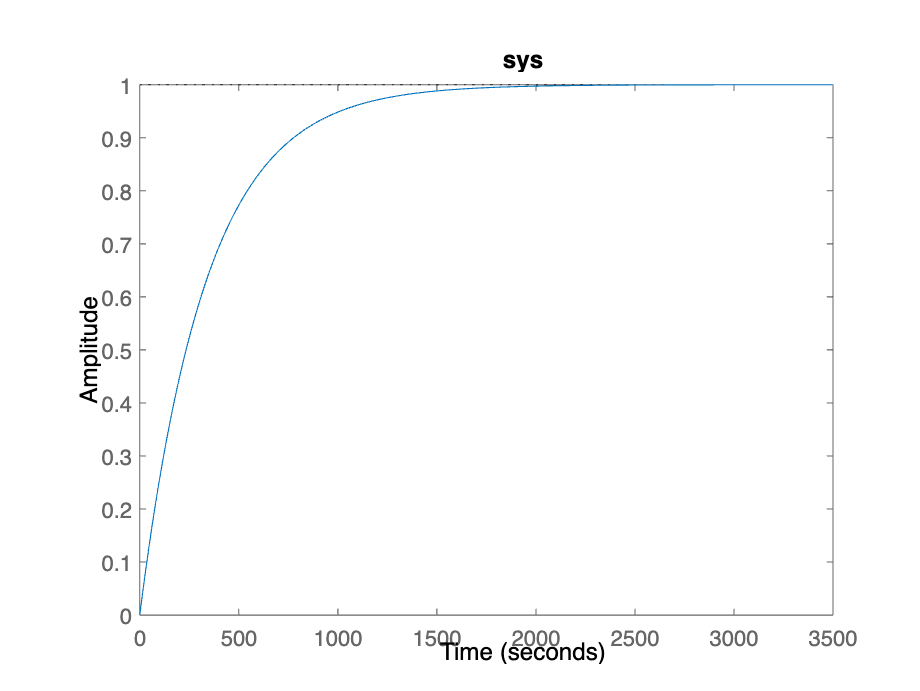

figure();
step(sys);
title("sys");

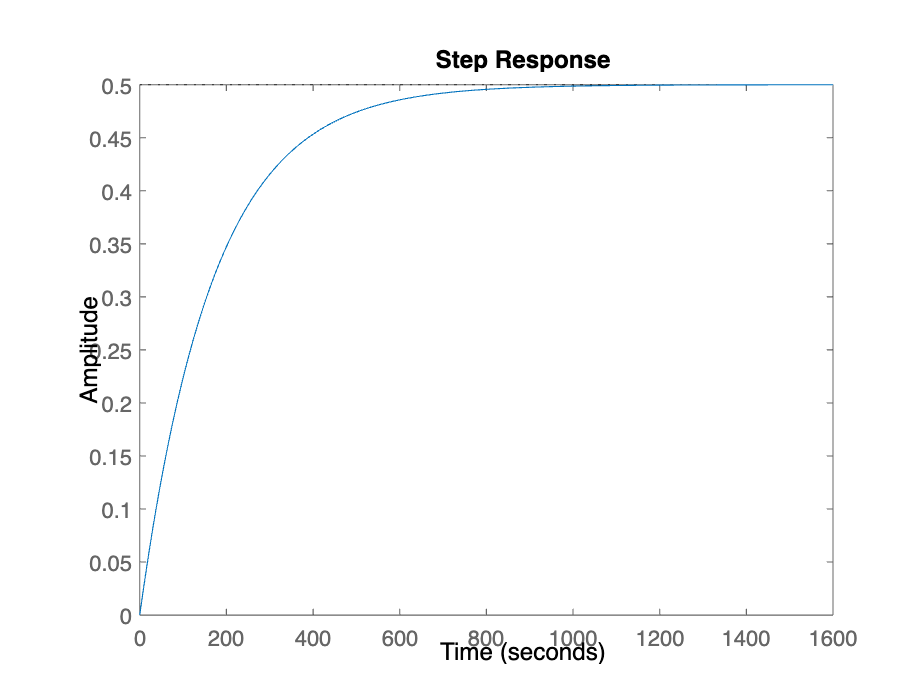

%%%2
sys_feedback=feedback(sys,1);
figure();
step(sys_feedback);

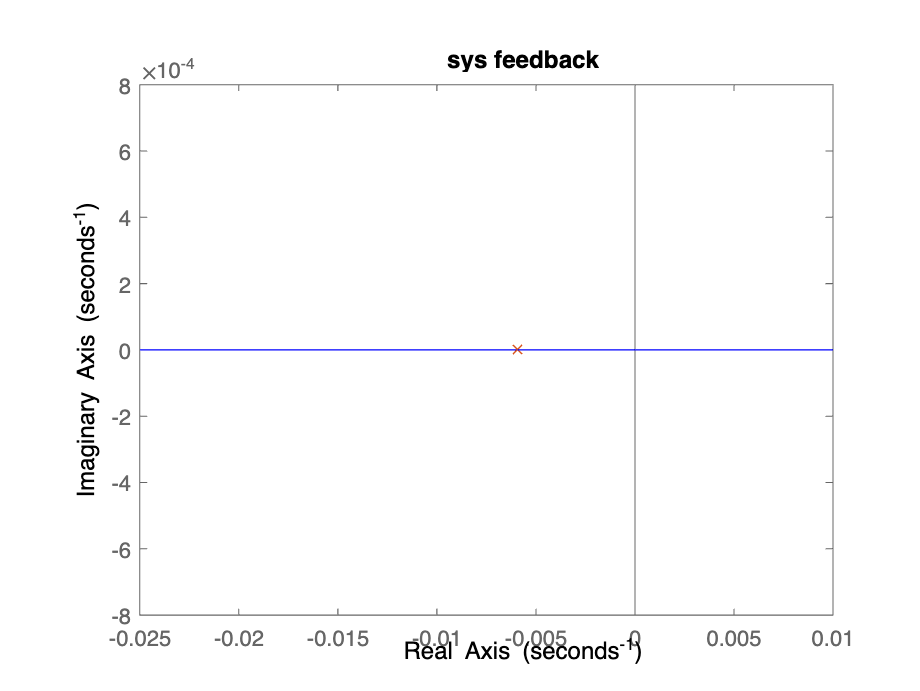

figure();
rlocus(sys_feedback);
title("sys feedback");
hold on
rlocus(-sys_feedback);

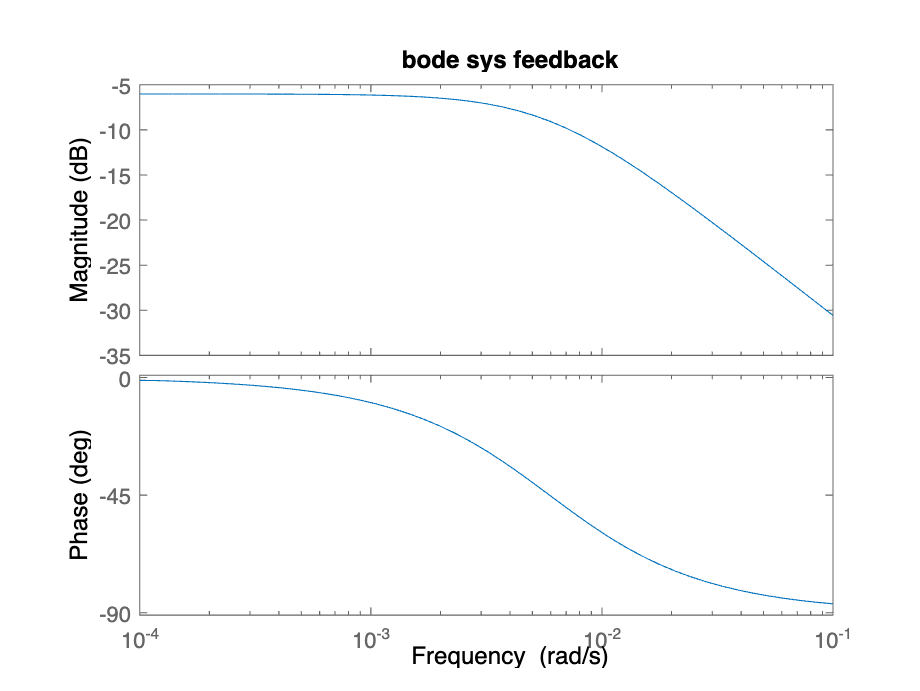


figure();
bode(sys_feedback);
title("bode sys feedback");

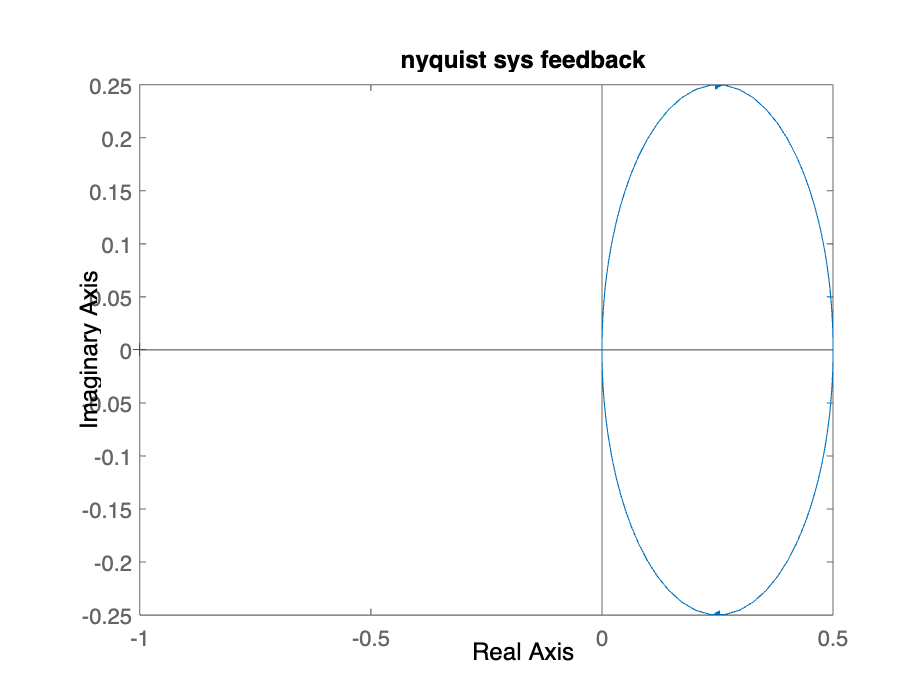

figure();
nyquist(sys_feedback);
title("nyquist sys feedback");

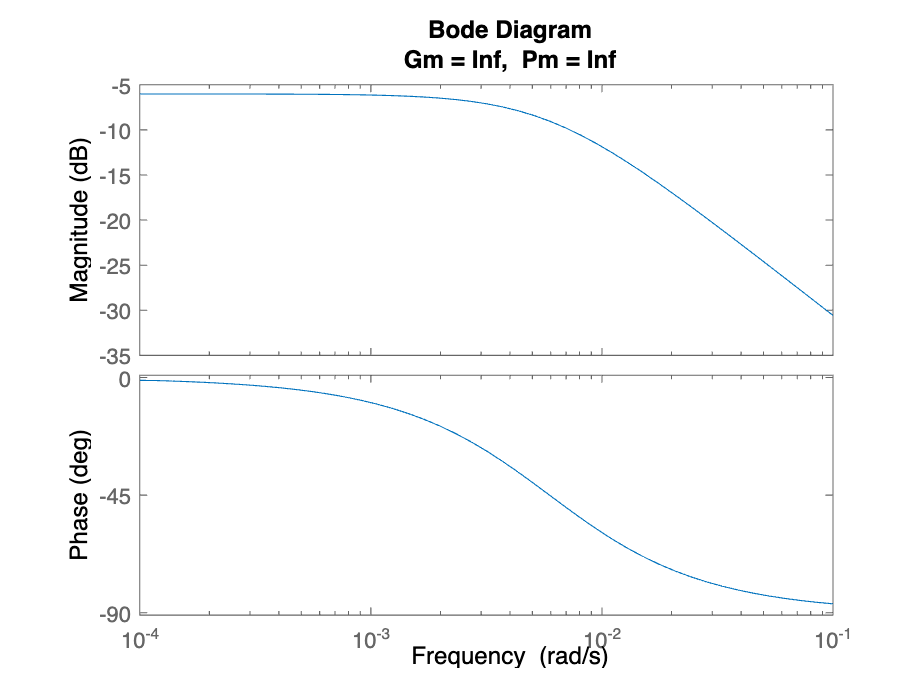

figure();
margin(sys_feedback);

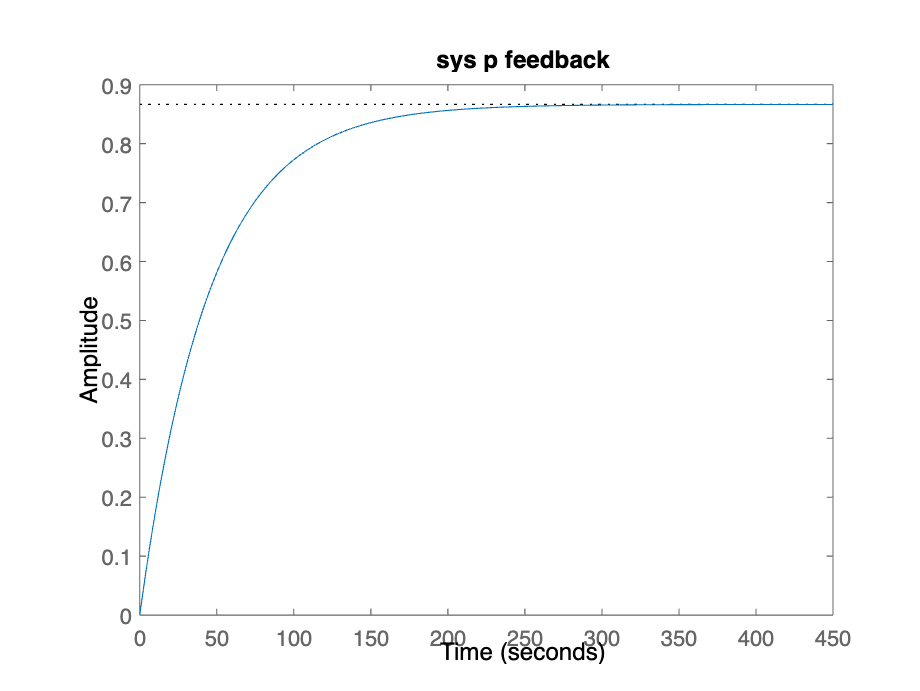

%%%3
Mp=0.12;
ts=180;
zeta=(sqrt((log(Mp))^2))/(sqrt(pi^2 + (log(Mp))^2));
wn=4/(ts*zeta);
%%%P
kp=4/(ts*0.002965)-1;
sys_p=kp*sys;
sys_p_feedback=feedback(sys_p,1);
figure();
step(sys_p_feedback);
title("sys p feedback");

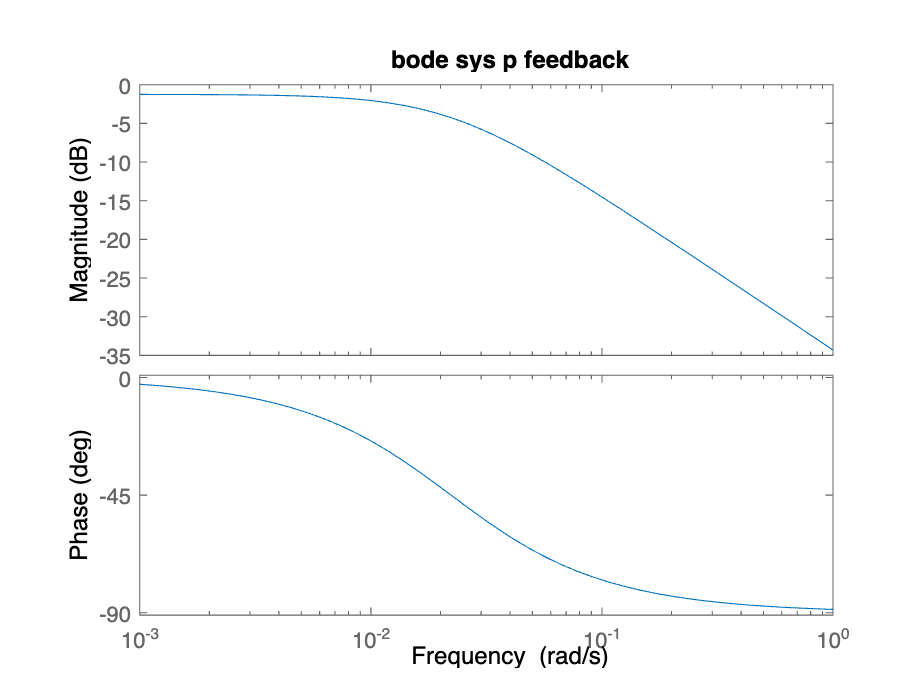

figure();
stepinfo_P=stepinfo(sys_p_feedback);

bode(sys_p_feedback);
title("bode sys p feedback");

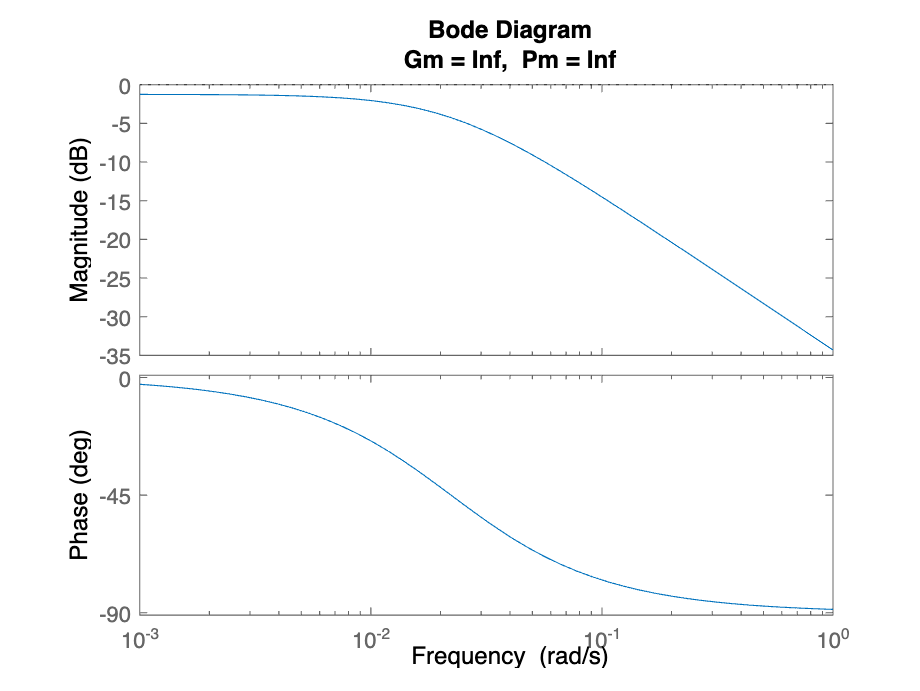

figure();

margin(sys_p_feedback);

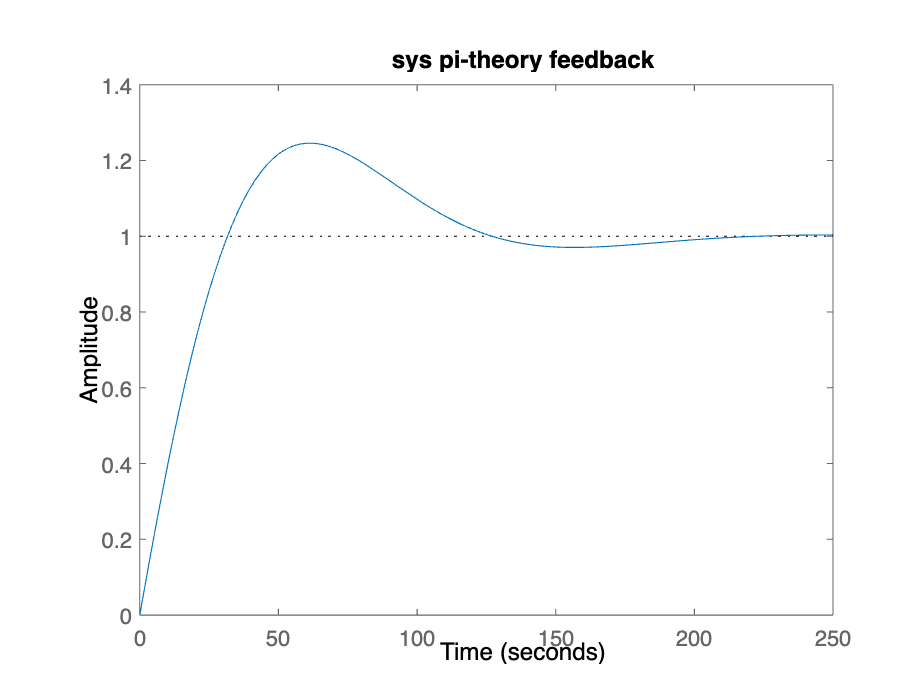

%%%PI theory
kp_2=(2*zeta*wn-0.002965)/(0.002965);
ki_2=(wn^2)/(0.002965);
Gc_pi=kp_2+ki_2/s;

sys_pi=Gc_pi*sys;
sys_pi_feedback=feedback(sys_pi,1);
stepinfo_PItheory=stepinfo(sys_pi_feedback);
figure;
step(sys_pi_feedback);
title("sys pi-theory feedback");

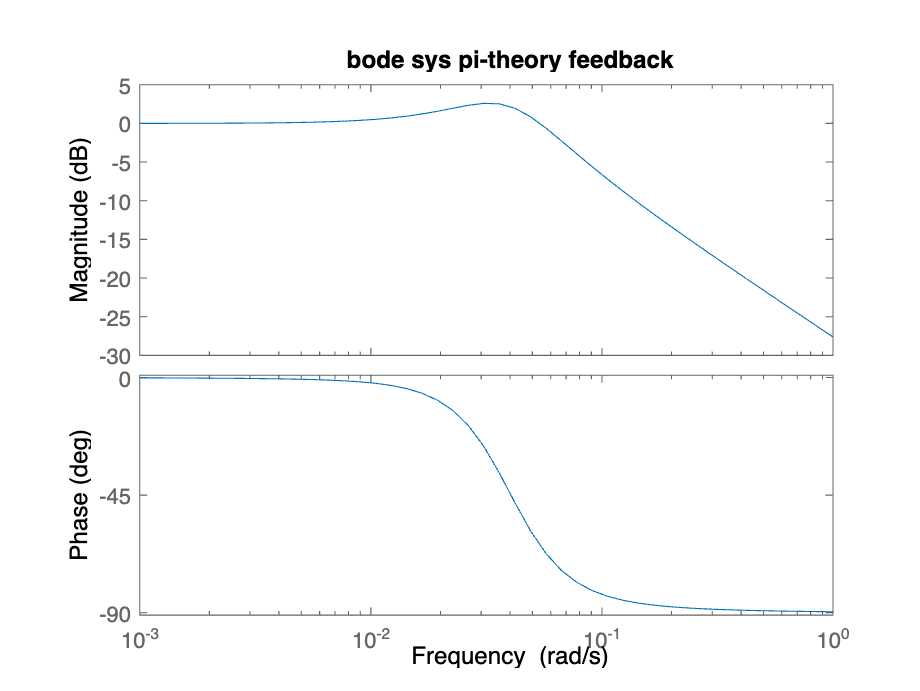

figure();
bode(sys_pi_feedback);
title("bode sys pi-theory feedback");

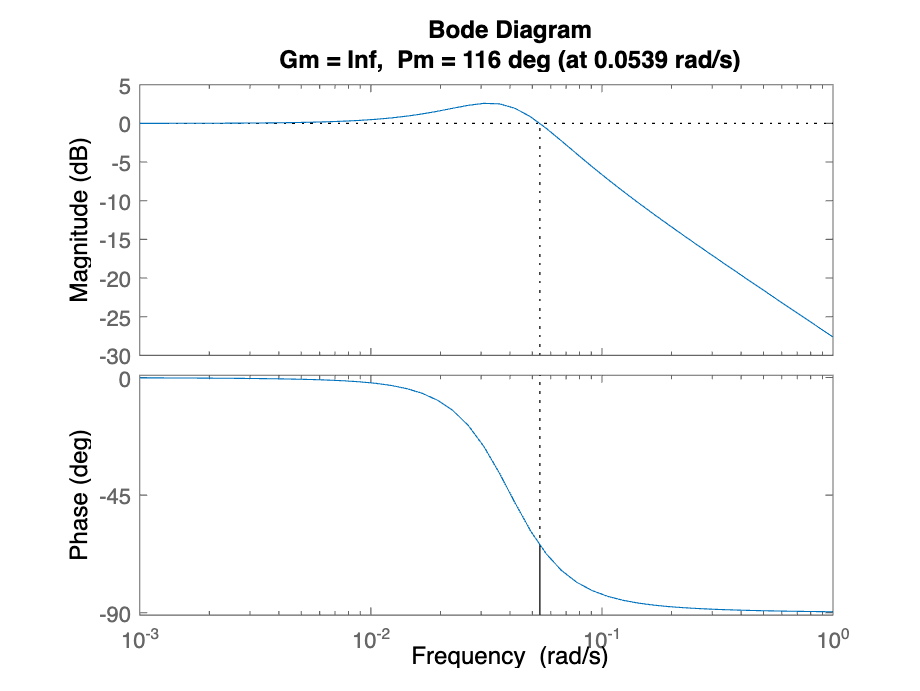

figure();

margin(sys_pi_feedback);

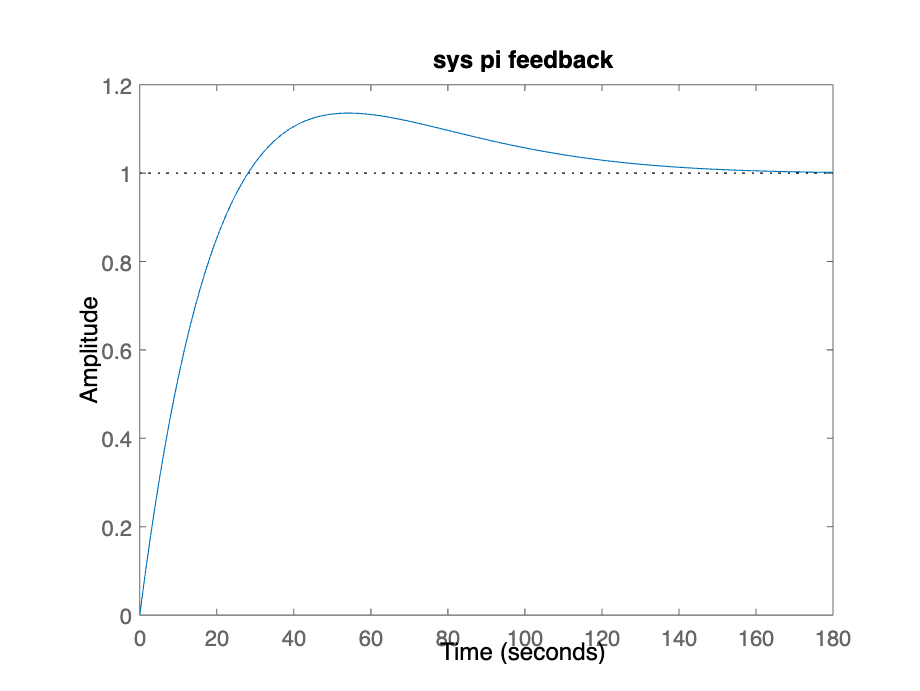

%%%PI
ki_2=(wn^2)/(0.002965);
Gc_pi=23+ki_2/s;

sys_pi=Gc_pi*sys;
sys_pi_feedback=feedback(sys_pi,1);
stepinfo_PI=stepinfo(sys_pi_feedback);
figure;
step(sys_pi_feedback);
title("sys pi feedback");

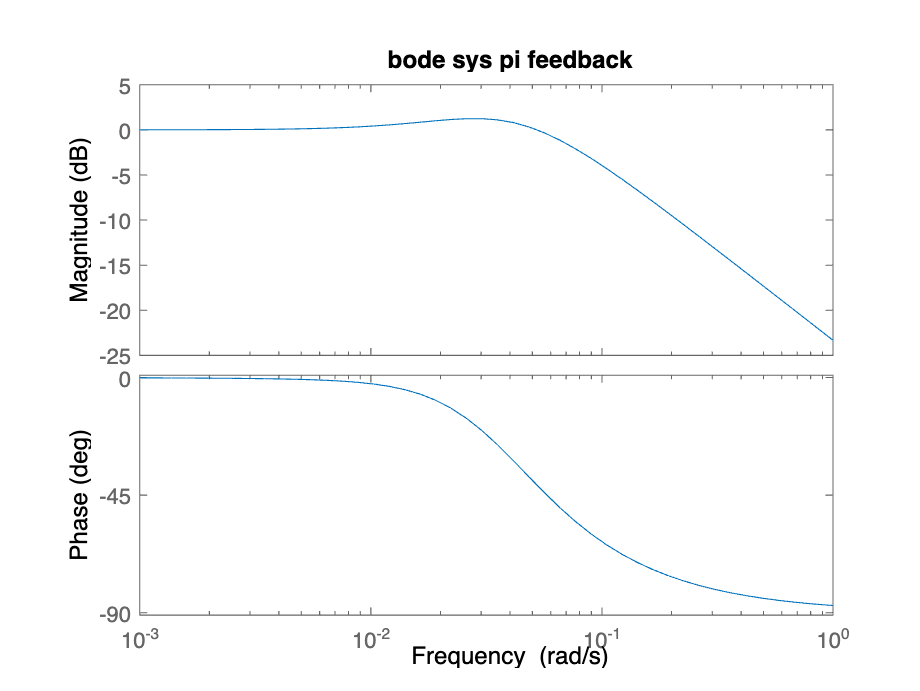

figure();
bode(sys_pi_feedback);
title("bode sys pi feedback");

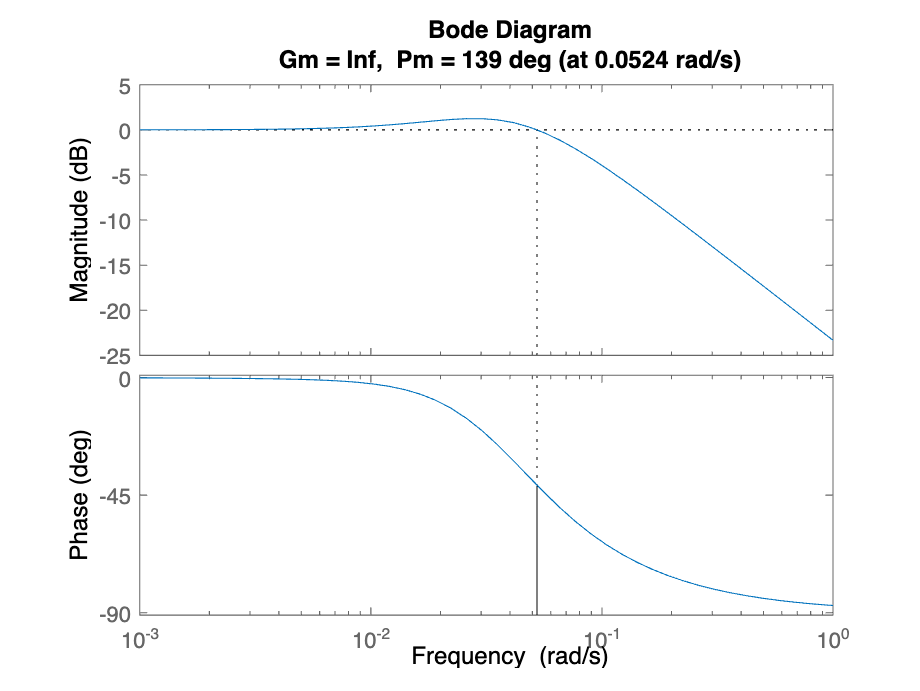

figure();

margin(sys_pi_feedback);

%%%PD
kd_3=1;
kp_3=(4*(kd_3*0.002965+1))/(ts*0.002965)-1;
Gc_pd=kp_3+kd_3*s;
sys_pd=Gc_pd*sys;
sys_pd_feedback=feedback(sys_pd,1);
stepinfo_PD=stepinfo(sys_pd_feedback)

stepinfo_PD = struct with fields:
         RiseTime: 98.8577
    TransientTime: 176.0209
     SettlingTime: 175.8701
      SettlingMin: 0.7806
      SettlingMax: 0.8669
        Overshoot: 0
       Undershoot: 0
             Peak: 0.8669
         PeakTime: 474.5024


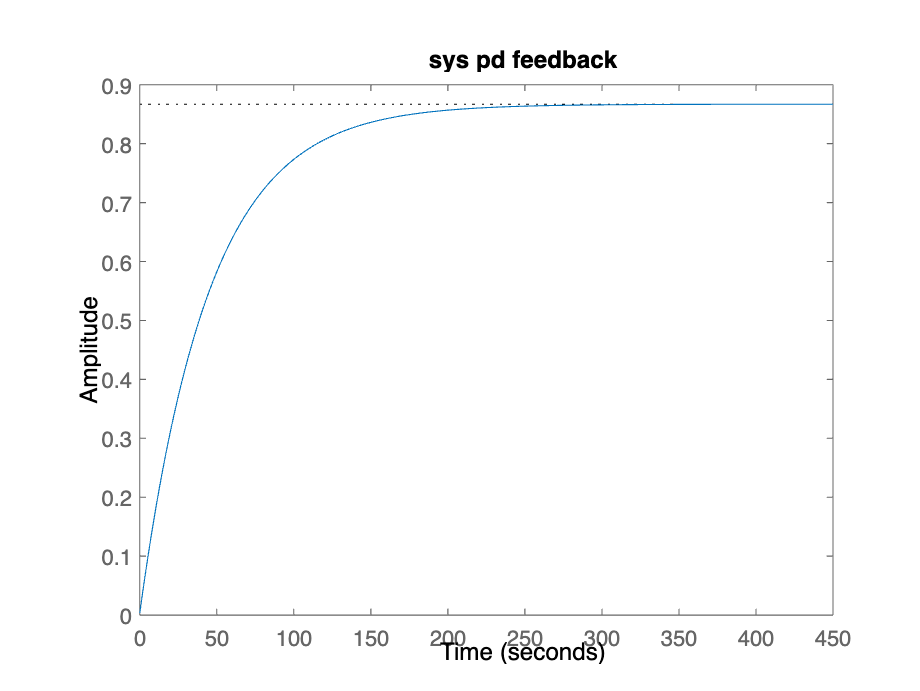

figure();
step(sys_pd_feedback);
title("sys pd feedback");

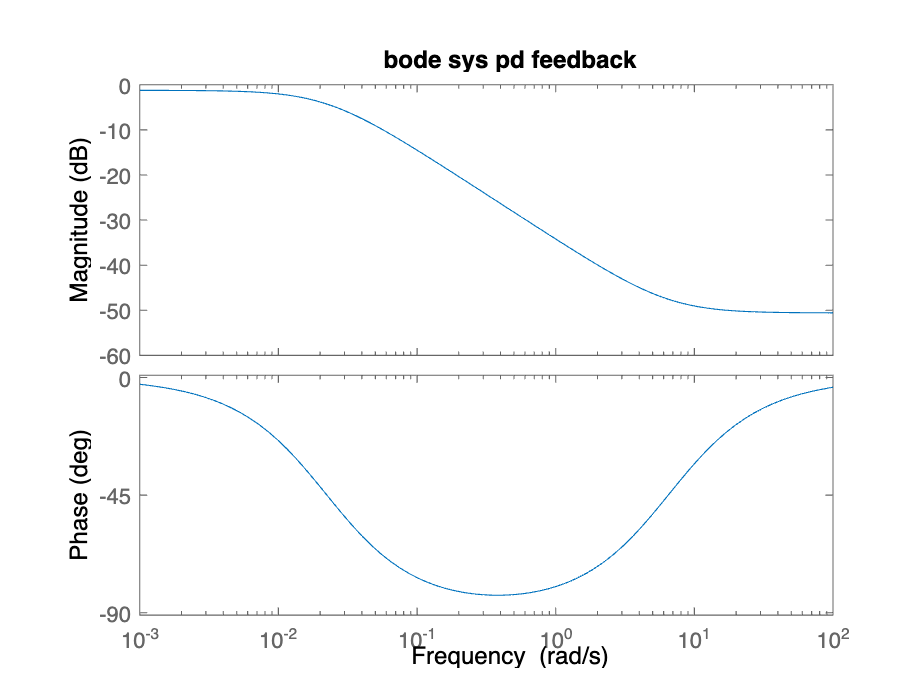

figure();
bode(sys_pd_feedback);
title("bode sys pd feedback");

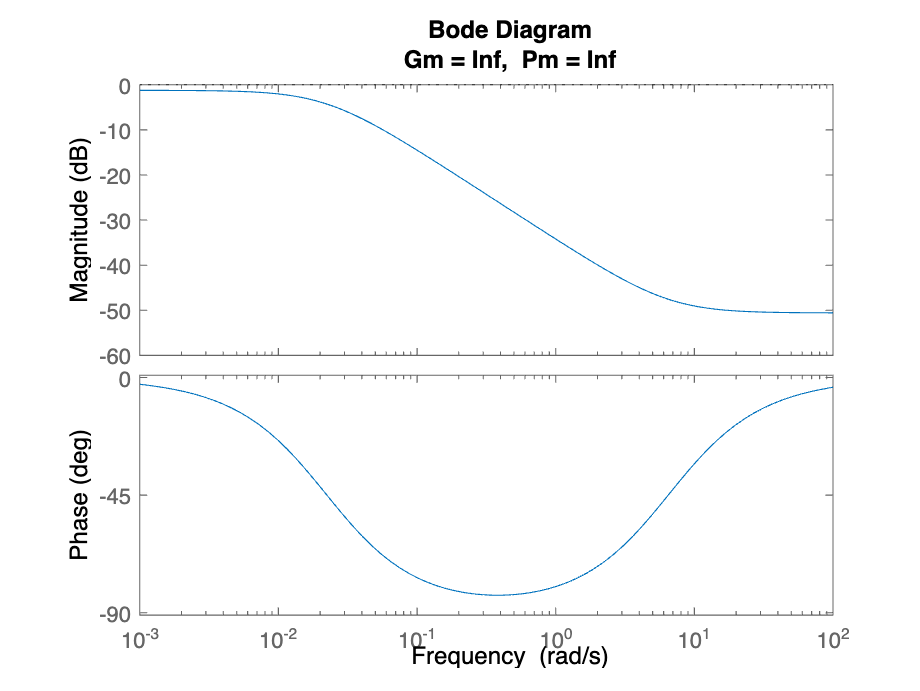

figure();
margin(sys_pd_feedback);

%%%PID when Kp is constant
kp_4=5;
kd_4=(1/0.002965)*((0.002965*(kp_4+1)/(2*zeta*wn))-1);
ki_4=(wn^2)*(1+0.002965*kd_4)/0.002965;

Gc_pid=kp + ki_4/s +kd_4*s;
 
sys_pid=Gc_pid*sys;
sys_pid_feedback=feedback(sys_pid,1);
stepinfo_PID_1=stepinfo(sys_pid_feedback)

stepinfo_PID_1 = struct with fields:
         RiseTime: 12.6737
    TransientTime: 123.5567
     SettlingTime: 180.5236
      SettlingMin: 0.9211
      SettlingMax: 1.4730
        Overshoot: 47.2989
       Undershoot: 149.8760
             Peak: 1.4988
         PeakTime: 0


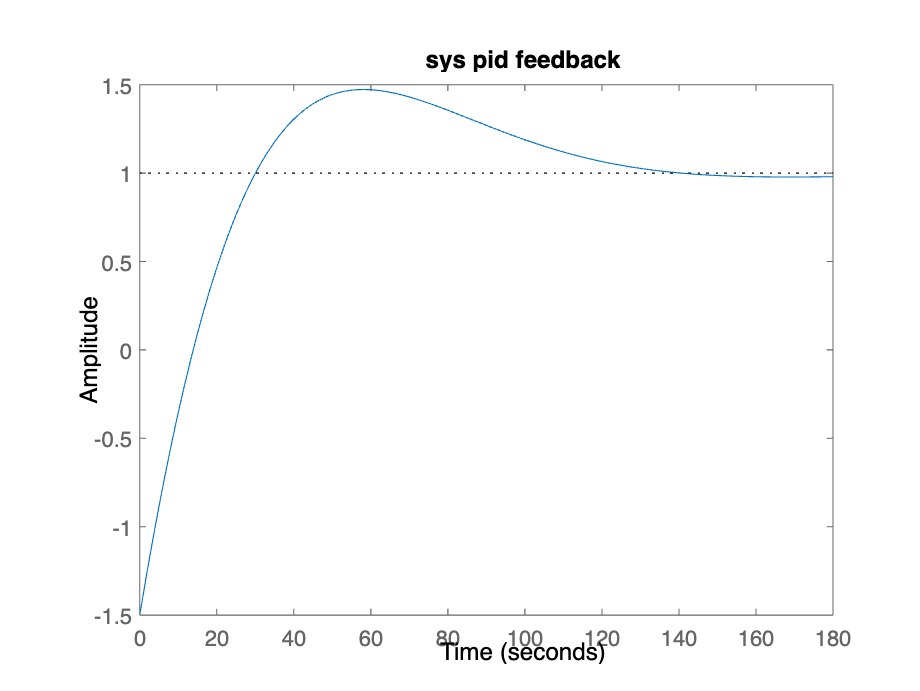

figure();
step(sys_pid_feedback);
title("sys pid feedback");

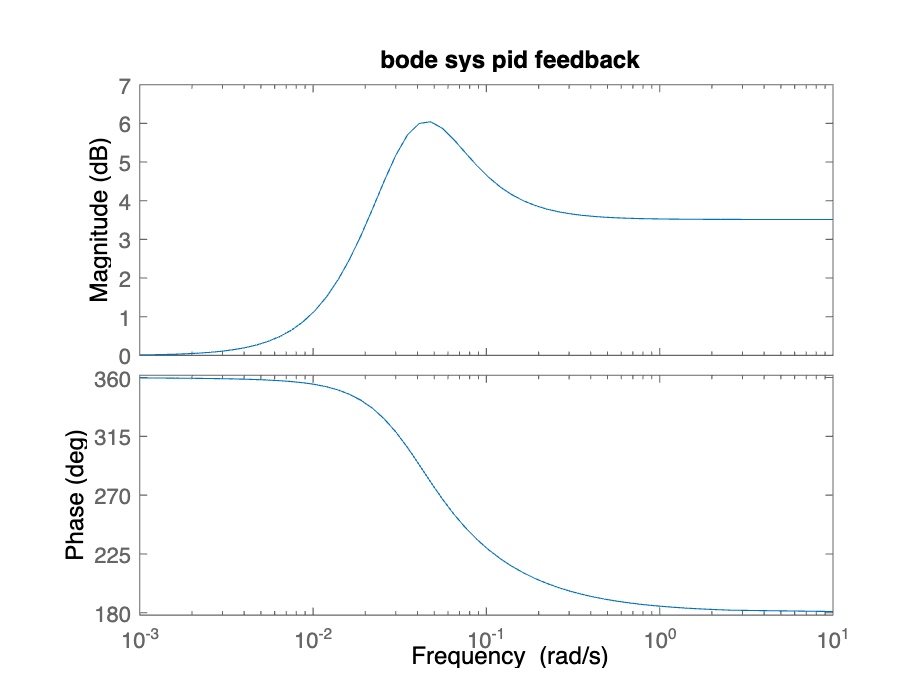

figure();
bode(sys_pid_feedback);
title("bode sys pid feedback");

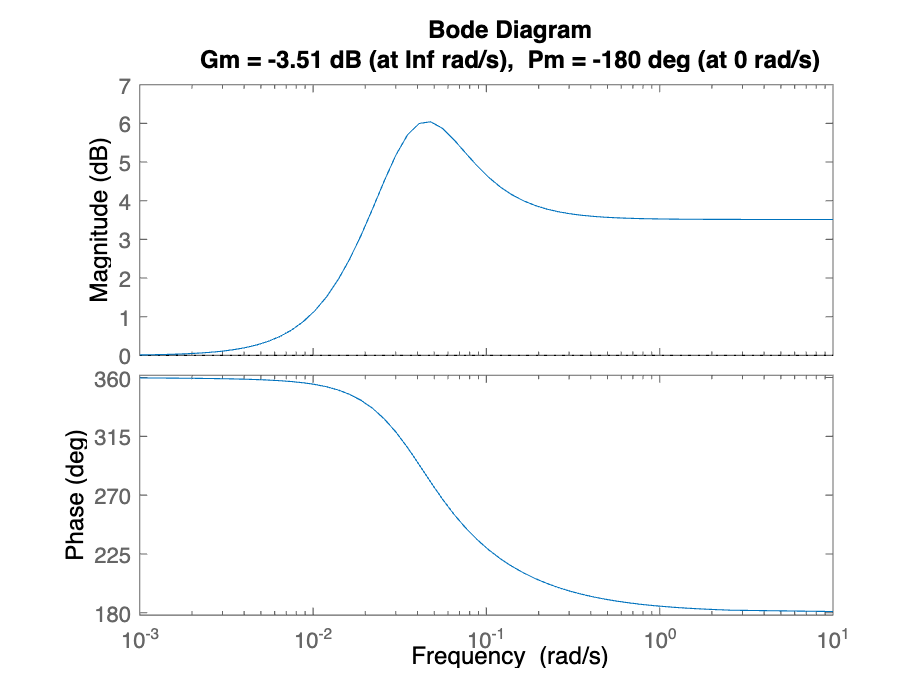

figure();
margin(sys_pid_feedback);

%%%PID when Ki is constant

ki_4=0.14;

kd_4=(0.002965*ki_4-wn^2)/(0.002965*(wn^2));
kp_4=(2*zeta*wn*(1+0.002965*kd_4)-0.002965)/0.002965;

Gc_pid=kp + ki_4/s +kd_4*s;
 
sys_pid=Gc_pid*sys;
sys_pid_feedback=feedback(sys_pid,1);
stepinfo_PID_2=stepinfo(sys_pid_feedback)

stepinfo_PID_2 = struct with fields:
         RiseTime: 9.9607
    TransientTime: 133.4841
     SettlingTime: 182.7136
      SettlingMin: 0.9687
      SettlingMax: 1.3996
        Overshoot: 39.9648
       Undershoot: 280.2832
             Peak: 2.8028
         PeakTime: 0


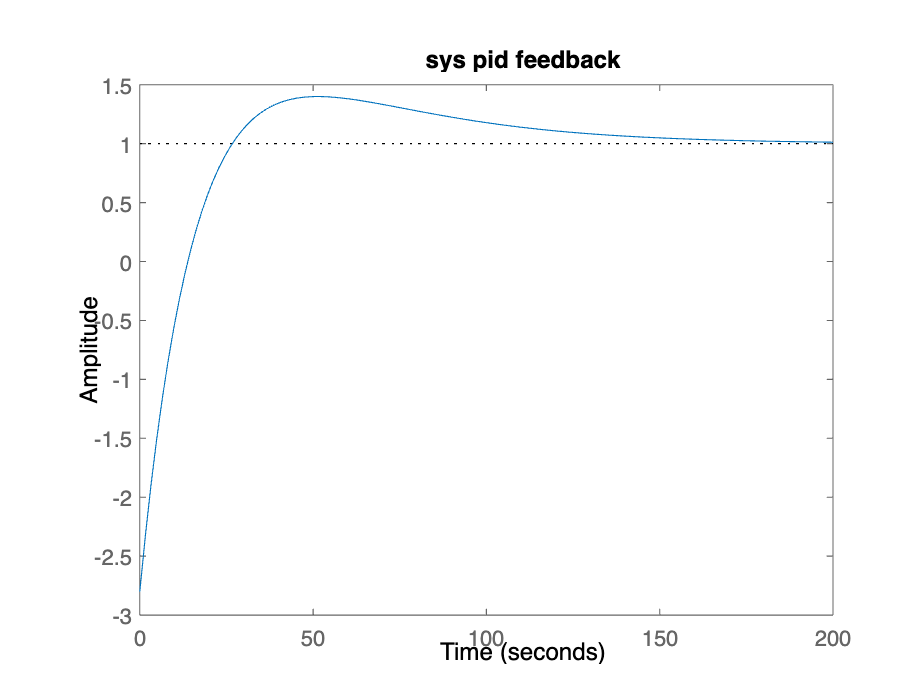

figure();
step(sys_pid_feedback);
title("sys pid feedback");

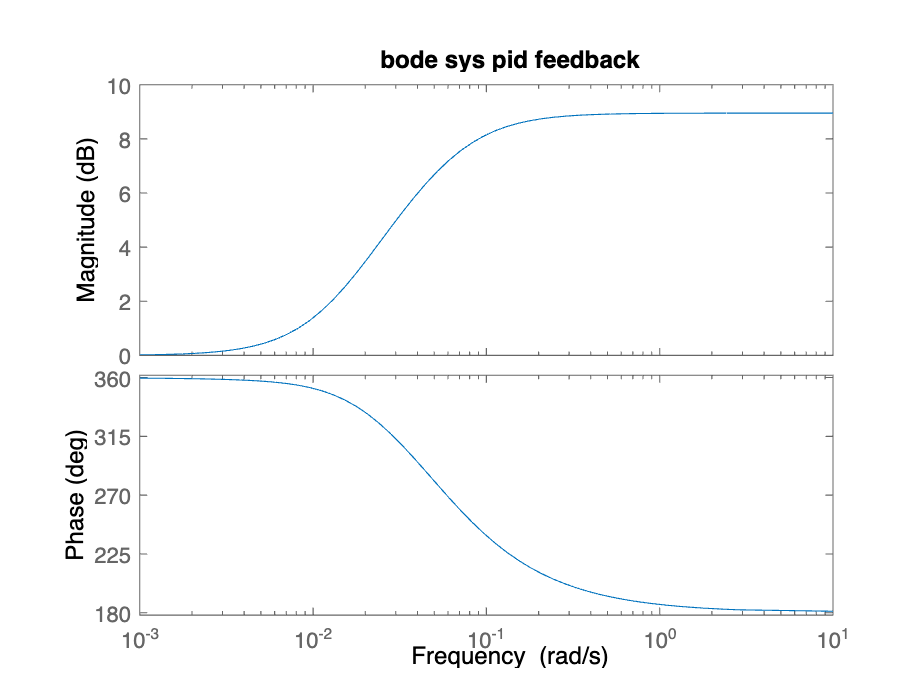

figure();
bode(sys_pid_feedback);
title("bode sys pid feedback");

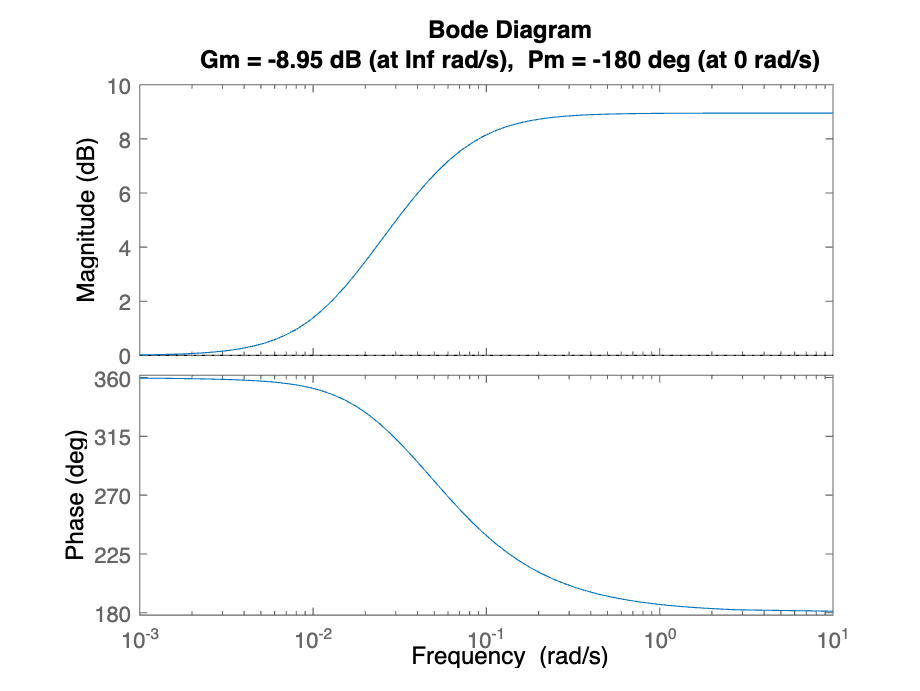

figure();
margin(sys_pid_feedback);

%%%PID when Kd in constant

kd_4=-255;
kp_4=(2*zeta*wn*(1+0.002965*kd_4))/(0.002965)-1;
ki_4=((wn^2)*(1+0.002965*kd_4))/(0.002965);
Gc_pid=kp + ki_4/s +kd_4*s;
 
sys_pid=Gc_pid*sys;
sys_pid_feedback=feedback(sys_pid,1);
stepinfo_PID_3=stepinfo(sys_pid_feedback)

stepinfo_PID_3 = struct with fields:
         RiseTime: 9.5621
    TransientTime: 133.9730
     SettlingTime: 194.9925
      SettlingMin: 0.9197
      SettlingMax: 1.3826
        Overshoot: 38.2605
       Undershoot: 310.1243
             Peak: 3.1012
         PeakTime: 0


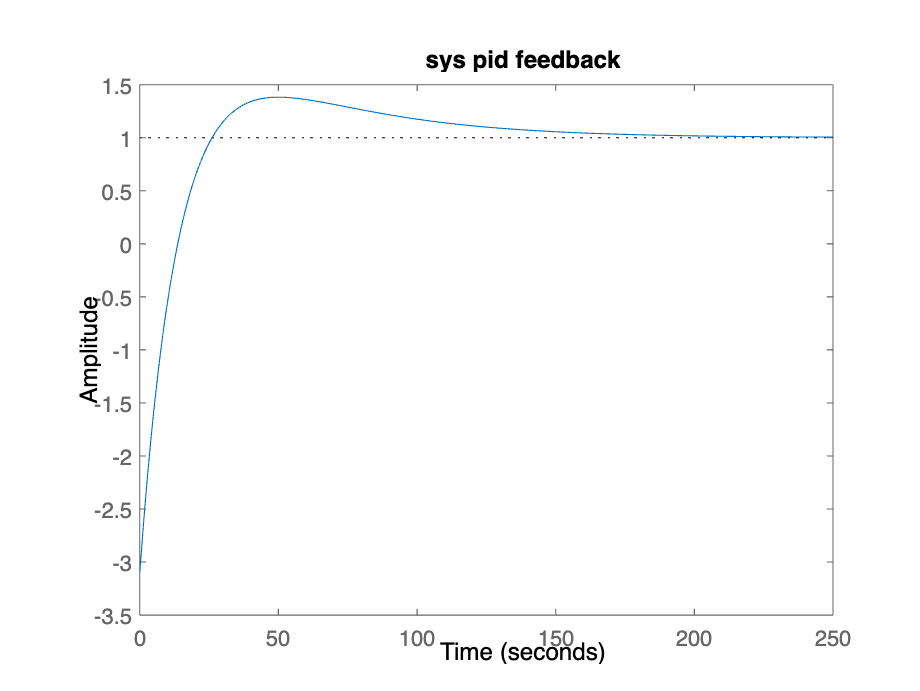

figure();
step(sys_pid_feedback);
title("sys pid feedback");

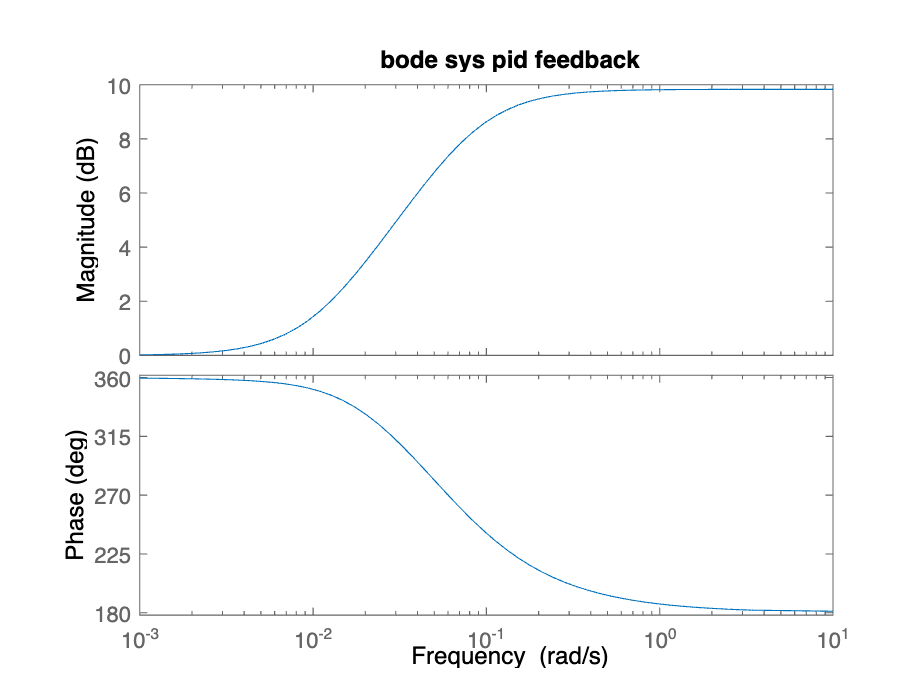

figure();
bode(sys_pid_feedback);
title("bode sys pid feedback");

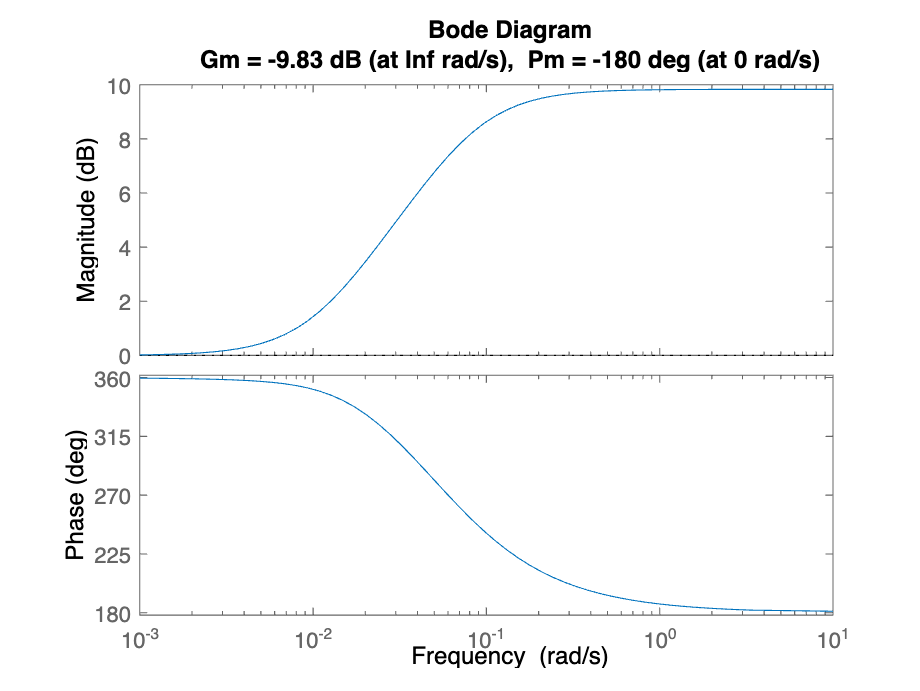

figure();
margin(sys_pid_feedback);

%%%lead
% Gc_lead=1*(22.73*s+1)/(22.73*s+0.1);
% sys_lead=Gc_lead*sys;
% sys_lead_feedback=feedback(sys_lead,1);
% stepinfo_lead=stepinfo(sys_lead_feedback)
% figure();
% step(sys_lead_feedback);
% title("sys lead feedback");
% figure();
% bode(sys_lead_feedback);
% title("bode sys lead feedback");
% figure();
% margin(sys_lead_feedback);
% close all;
beta = acos(zeta);
beta = rad2deg(beta);
xpoint = -zeta*wn

xpoint = -0.0222

tan_beta = tan((beta*pi)/180);
ypoint = tan_beta*zeta*wn

ypoint = 0.0329


num1 = 0.002965;
den1 = [1 0.002965];
g1 = tf (num1,den1);



teta_p = 30;
teta_z = 89.9;
x = ypoint/(tan((30*pi)/180));
p = x + 0.0222

p = 0.0792

y = ypoint/(tan((89.9*pi)/180));
z = 0.0222-y

z = 0.0221


q = -0.0222 + 0.0328j ;
num2 = 0.002965*(q+z);
den2 = (q+p)*(q+0.002965);
%k = abs(den2/num2)
k=50

k = 50

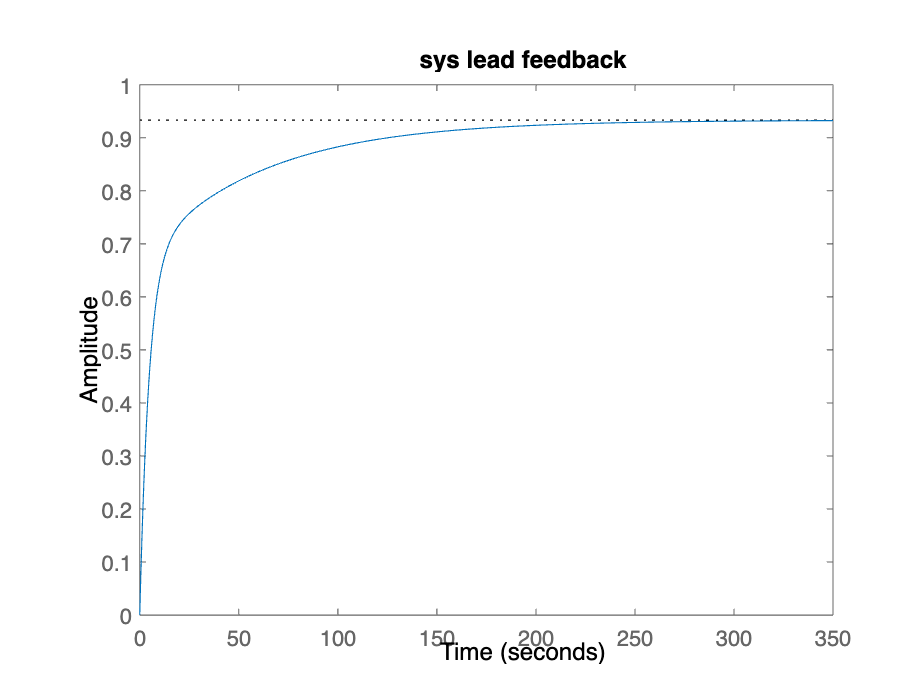



num3 = [k*0.002965 k*0.002965*z];
den3 = [1 0.002965+p 0.002965*p];
g2 = tf(num3,den3);
sys_lead_feedback=feedback(g2,1);
figure;
step(sys_lead_feedback);
title('sys lead feedback')

stepinfo_lead=stepinfo(sys_lead_feedback)

stepinfo_lead = struct with fields:
         RiseTime: 61.7760
    TransientTime: 160.3738
     SettlingTime: 160.3738
      SettlingMin: 0.8405
      SettlingMax: 0.9325
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9325
         PeakTime: 361.0815


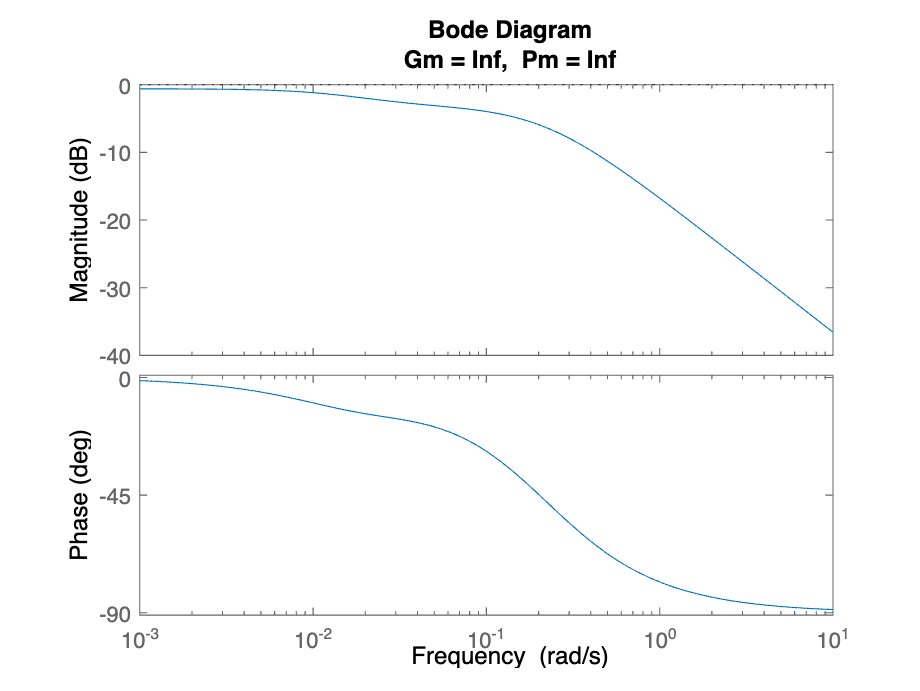

figure;
margin(sys_lead_feedback);

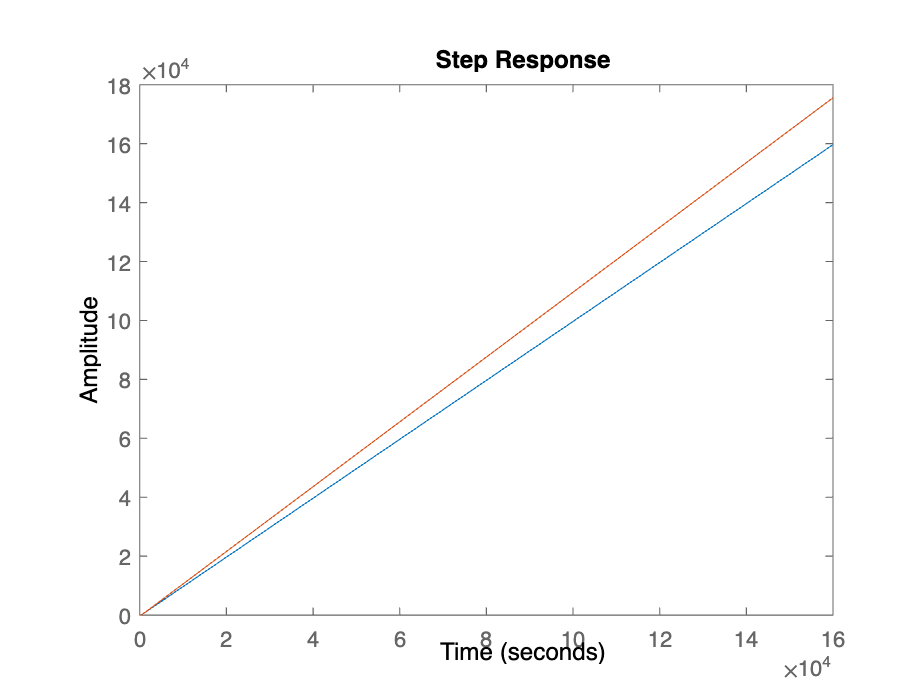

%%%lag 
K_old = 1;
K_new = 1.1;
z2 = -xpoint/10;
p2 = (z2*K_old)/K_new;
num4 = [0.002965 0.002965*z2];
den4 = [1 0.002965+p2 0.002965*p2];
g3 = tf(num4,den4);
figure();
step(g1/s);
hold on
step(g3/s);

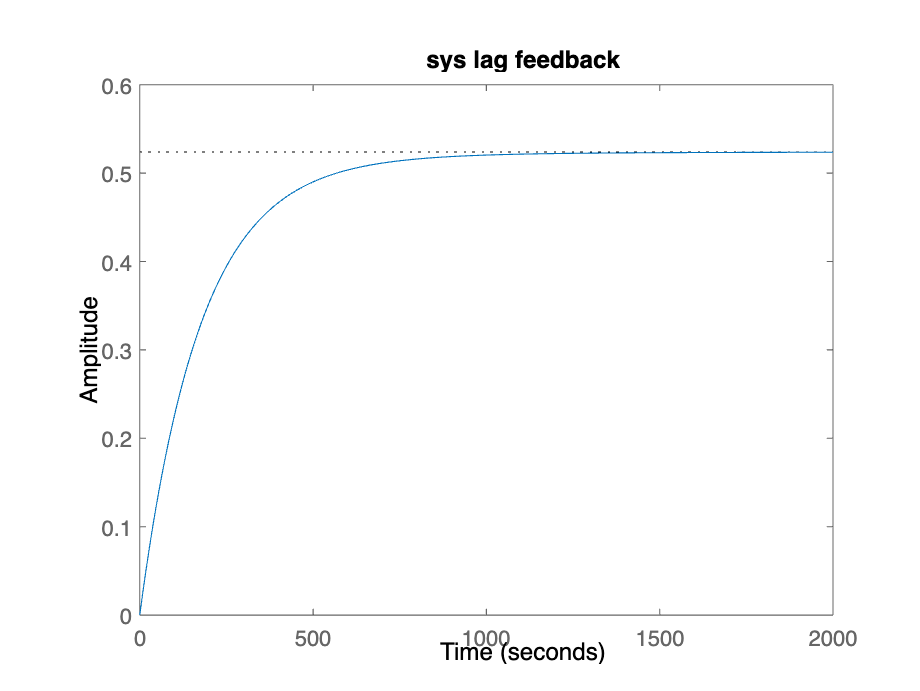

sys_lag_feedback=feedback(g3,1);
figure;
step(sys_lag_feedback);
title('sys lag feedback')

stepinfo_lag=stepinfo(sys_lag_feedback)

stepinfo_lag = struct with fields:
         RiseTime: 397.8406
    TransientTime: 736.2314
     SettlingTime: 736.2314
      SettlingMin: 0.4732
      SettlingMax: 0.5237
        Overshoot: 0
       Undershoot: 0
             Peak: 0.5237
         PeakTime: 2.2267e+03


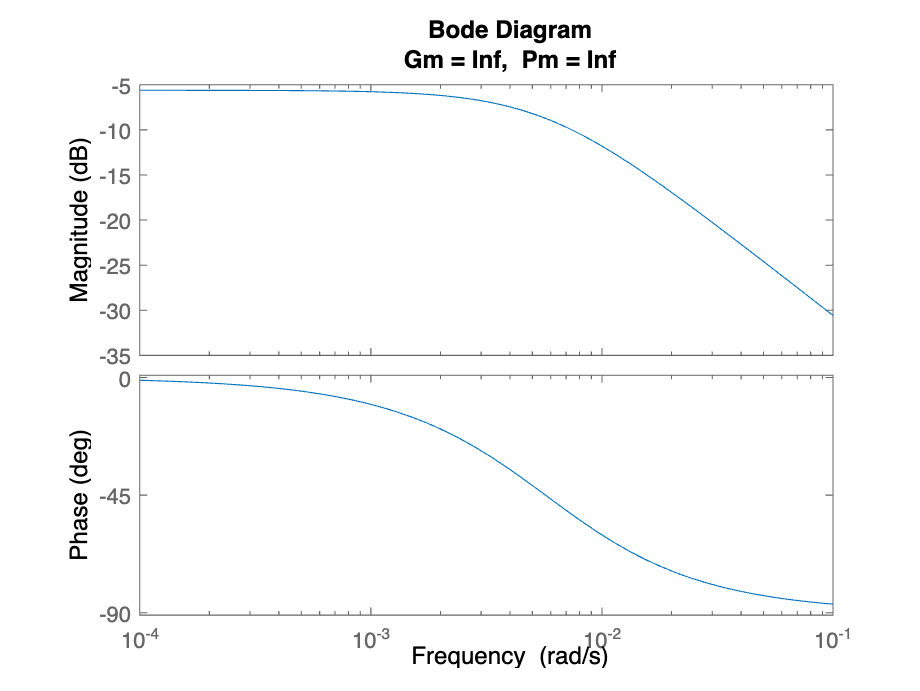

figure;
margin(sys_lag_feedback);

%%%%%
Gc_lag=10*(s+0.0464)/(s+0.011785);
sys_lag=Gc_lag*sys;
sys_lag1_feedback=feedback(sys_lag,1);
stepinfo_lag1=stepinfo(sys_lag1_feedback)

stepinfo_lag1 = struct with fields:
         RiseTime: 32.7090
    TransientTime: 134.0198
     SettlingTime: 134.0198
      SettlingMin: 0.8984
      SettlingMax: 1.1325
        Overshoot: 16.1267
       Undershoot: 0
             Peak: 1.1325
         PeakTime: 74.6714


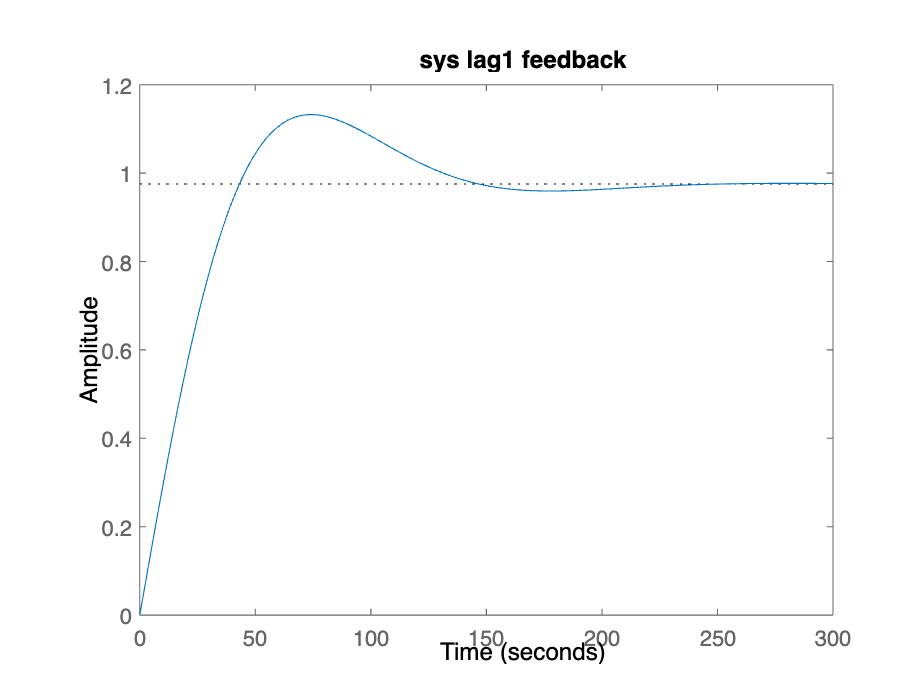

figure();
step(sys_lag1_feedback);
title("sys lag1 feedback");

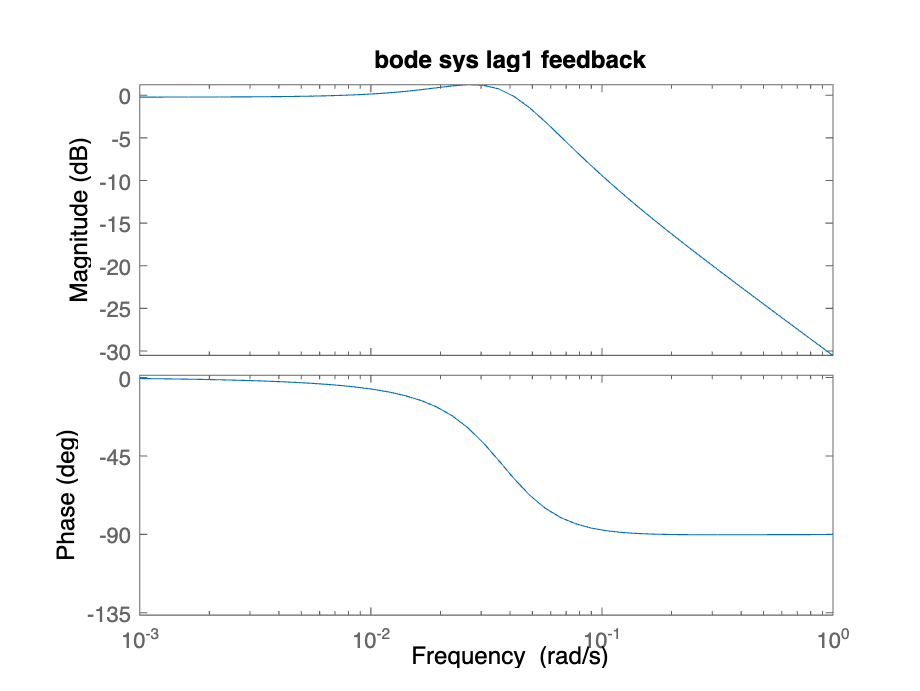

figure();
bode(sys_lag1_feedback);
title("bode sys lag1 feedback");

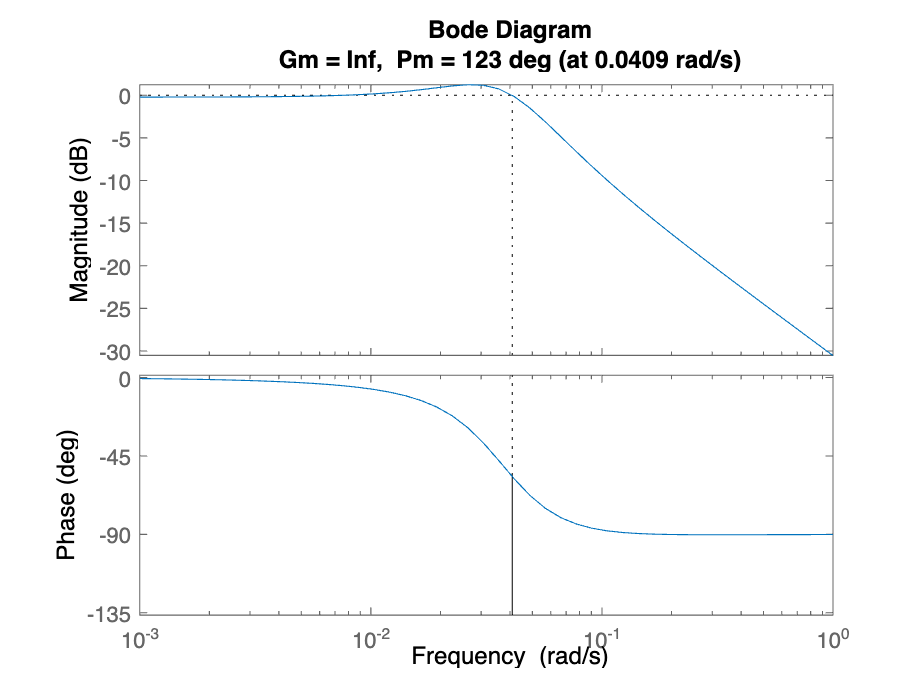

figure();
margin(sys_lag1_feedback);

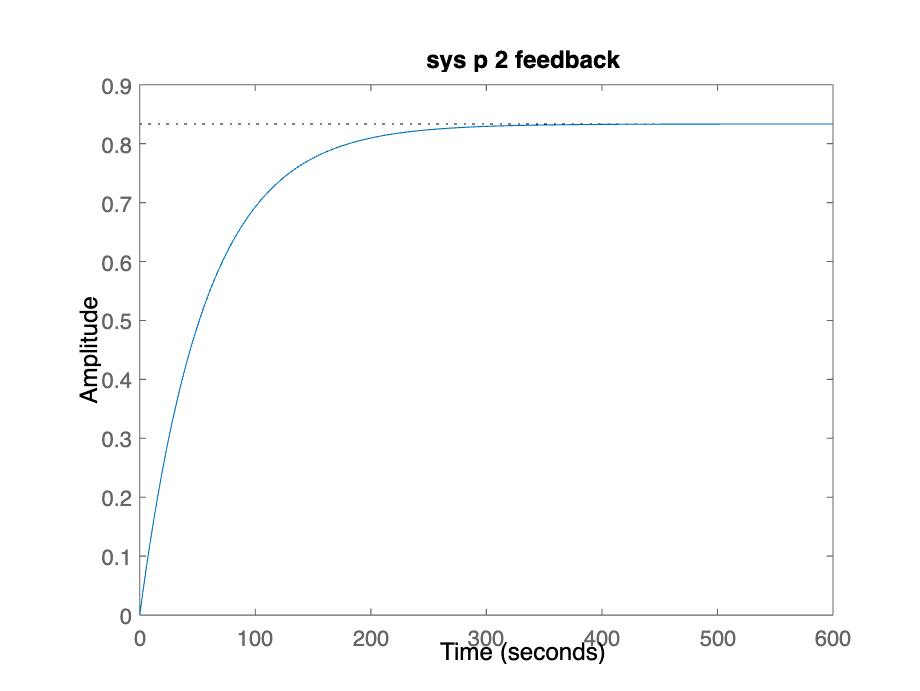

%%P changed
kp=5;
sys_p_2=kp*sys;
sys_p_2_feedback=feedback(sys_p_2,1);
figure();
step(sys_p_2_feedback);
title("sys p 2 feedback");

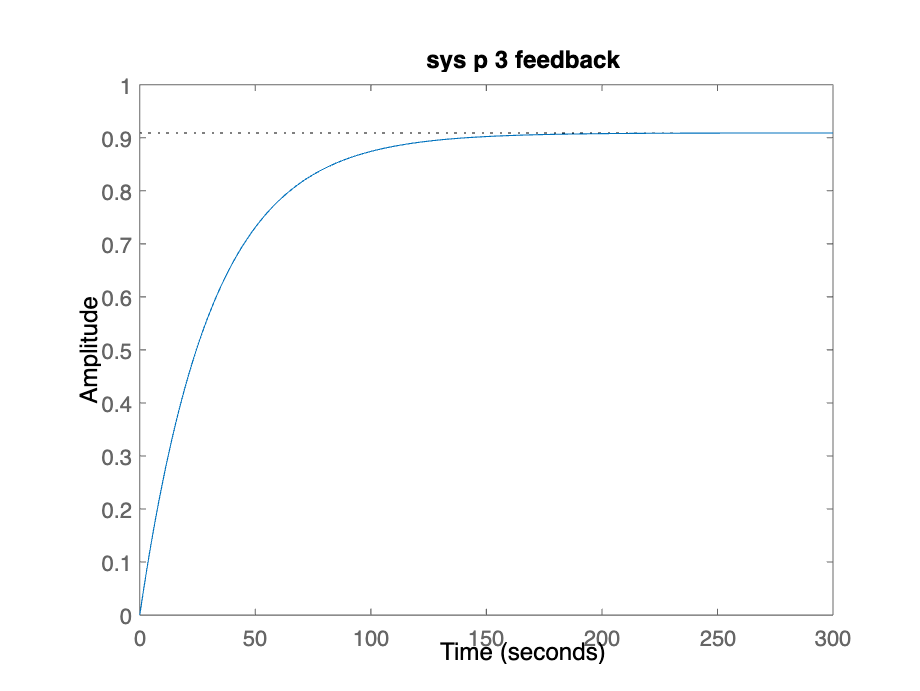


kp=10;
sys_p_3=kp*sys;
sys_p_3_feedback=feedback(sys_p_3,1);
figure();
step(sys_p_3_feedback);
title("sys p 3 feedback");

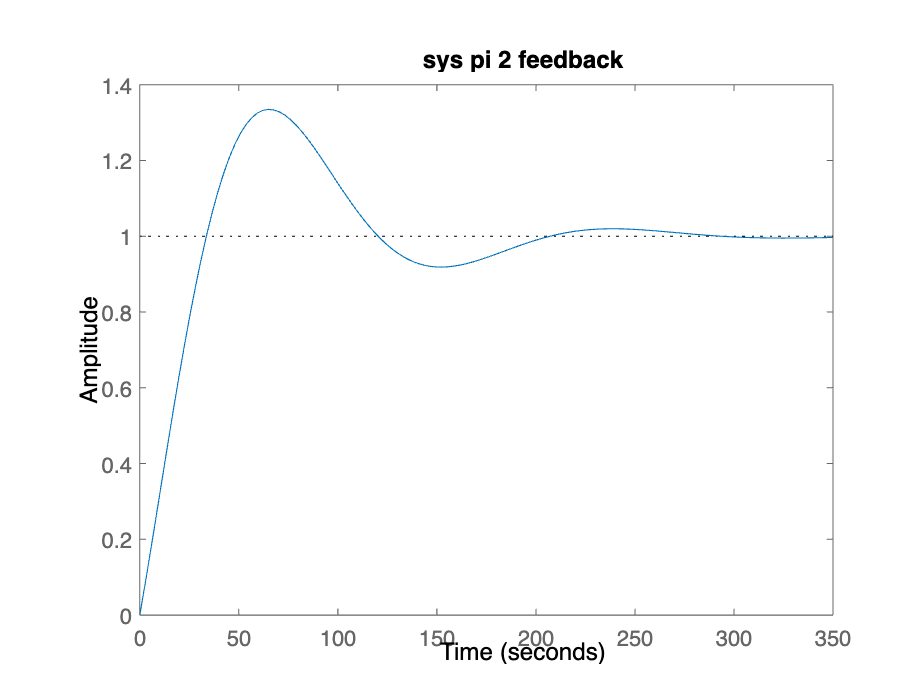

%%PI changed
ki_2=(wn^2)/(0.002965);
Gc_pi=10+ki_2/s;

sys_pi=Gc_pi*sys;
sys_pi_feedback=feedback(sys_pi,1);
stepinfo_PI=stepinfo(sys_pi_feedback);
figure;
step(sys_pi_feedback);
title("sys pi 2 feedback");

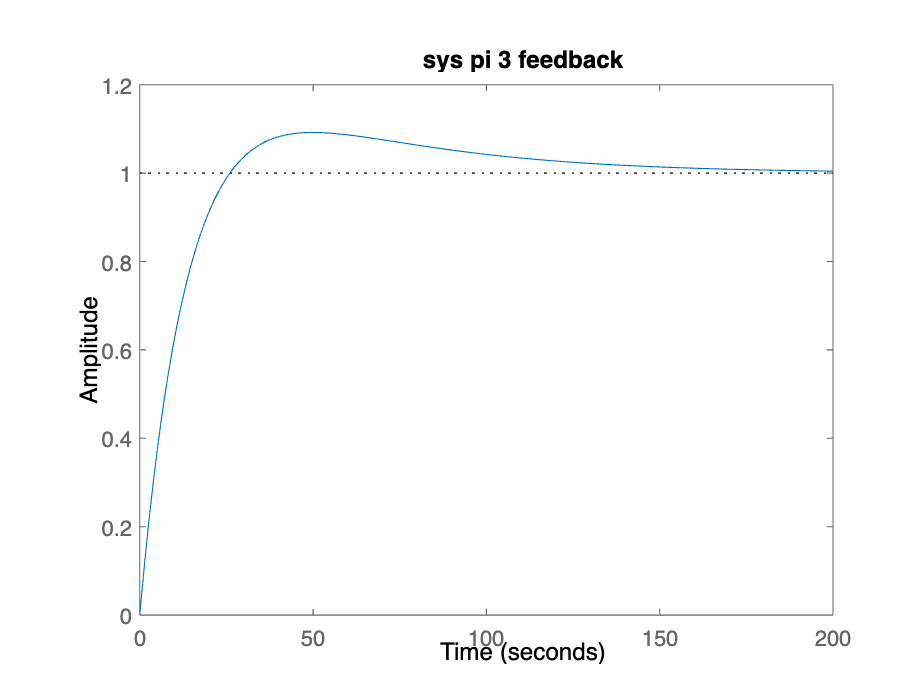


ki_2=(wn^2)/(0.002965);
Gc_pi=30+ki_2/s;

sys_pi=Gc_pi*sys;
sys_pi_feedback=feedback(sys_pi,1);
stepinfo_PI=stepinfo(sys_pi_feedback);
figure;
step(sys_pi_feedback);
title("sys pi 3 feedback");

%%PD changed
%%%PD
kd_3=0.1;
kp_3=(4*(kd_3*0.002965+1))/(ts*0.002965)-1;
Gc_pd=kp_3+kd_3*s;
sys_pd=Gc_pd*sys;
sys_pd_feedback=feedback(sys_pd,1);
stepinfo_PD=stepinfo(sys_pd_feedback)

stepinfo_PD = struct with fields:
         RiseTime: 98.8532
    TransientTime: 176.0209
     SettlingTime: 176.0058
      SettlingMin: 0.7800
      SettlingMax: 0.8666
        Overshoot: 0
       Undershoot: 0
             Peak: 0.8666
         PeakTime: 474.5022


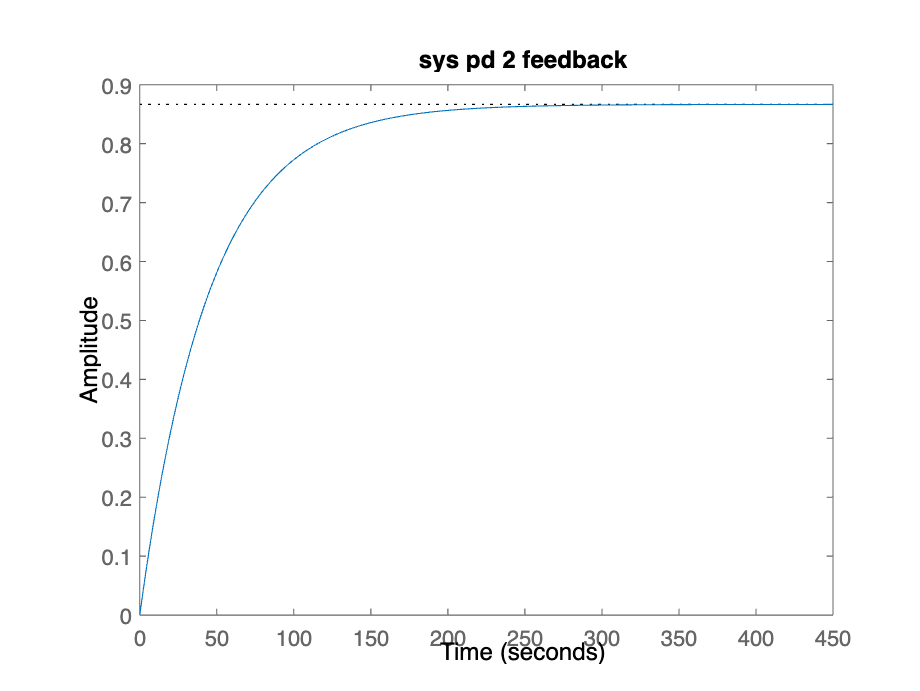

figure();
step(sys_pd_feedback);
title("sys pd 2 feedback");


kd_3=10;
kp_3=(4*(kd_3*0.002965+1))/(ts*0.002965)-1;
Gc_pd=kp_3+kd_3*s;
sys_pd=Gc_pd*sys;
sys_pd_feedback=feedback(sys_pd,1);
stepinfo_PD=stepinfo(sys_pd_feedback)

stepinfo_PD = struct with fields:
         RiseTime: 98.8605
    TransientTime: 176.0215
     SettlingTime: 174.5134
      SettlingMin: 0.7863
      SettlingMax: 0.8704
        Overshoot: 0
       Undershoot: 0
             Peak: 0.8704
         PeakTime: 474.5040


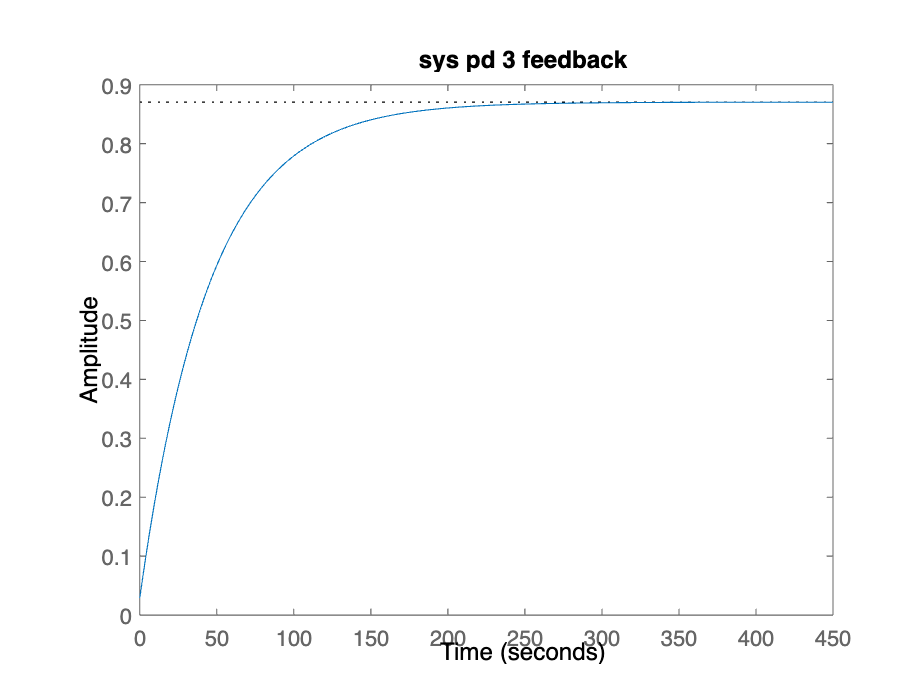

figure();
step(sys_pd_feedback);
title("sys pd 3 feedback");

%%PID changed
%%%PID when Ki is constant
ki_4=0.01;
kd_4=(0.002965*ki_4-wn^2)/(0.002965*(wn^2));
kp_4=(2*zeta*wn*(1+0.002965*kd_4)-0.002965)/0.002965;
Gc_pid=kp + ki_4/s +kd_4*s;
sys_pid=Gc_pid*sys;
sys_pid_feedback=feedback(sys_pid,1);
stepinfo_PID_2=stepinfo(sys_pid_feedback)

stepinfo_PID_2 = struct with fields:
         RiseTime: 1.7832
    TransientTime: 2.2737
     SettlingTime: NaN
      SettlingMin: 0.9001
      SettlingMax: 0.9358
        Overshoot: 0
       Undershoot: 5.2578e+03
             Peak: 52.5777
         PeakTime: 0


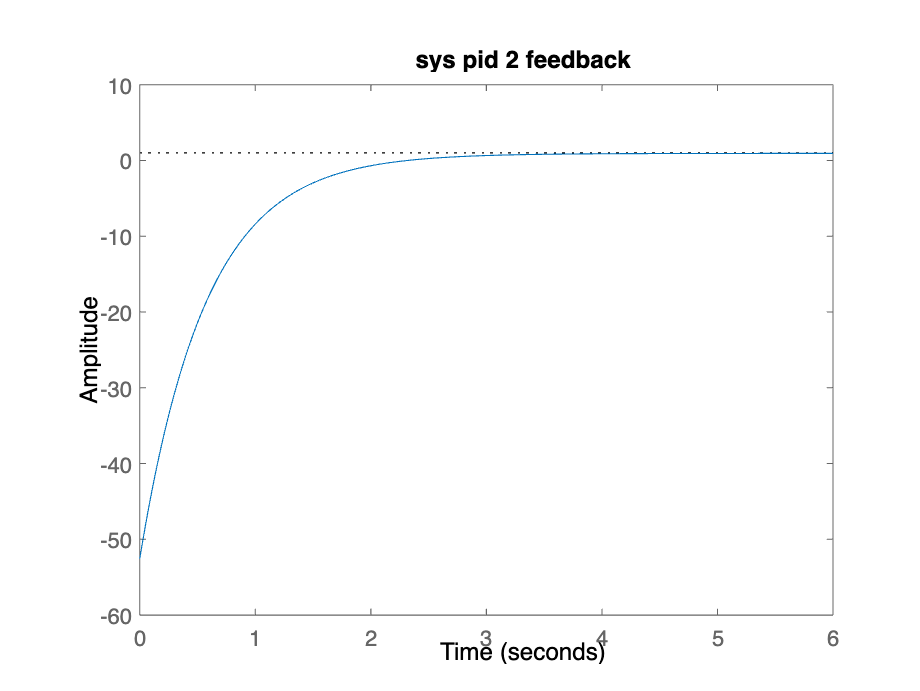

figure();
step(sys_pid_feedback);
title("sys pid 2 feedback");


ki_4=5;
kd_4=(0.002965*ki_4-wn^2)/(0.002965*(wn^2));
kp_4=(2*zeta*wn*(1+0.002965*kd_4)-0.002965)/0.002965;
Gc_pid=kp + ki_4/s +kd_4*s;
sys_pid=Gc_pid*sys;
sys_pid_feedback=feedback(sys_pid,1);
stepinfo_PID_2=stepinfo(sys_pid_feedback)

stepinfo_PID_2 = struct with fields:
         RiseTime: 8.3539
    TransientTime: 2.2245e+03
     SettlingTime: 953.3015
      SettlingMin: 0.9143
      SettlingMax: 1.0928
        Overshoot: 9.2768
       Undershoot: 0
             Peak: 1.0928
         PeakTime: 79.0851


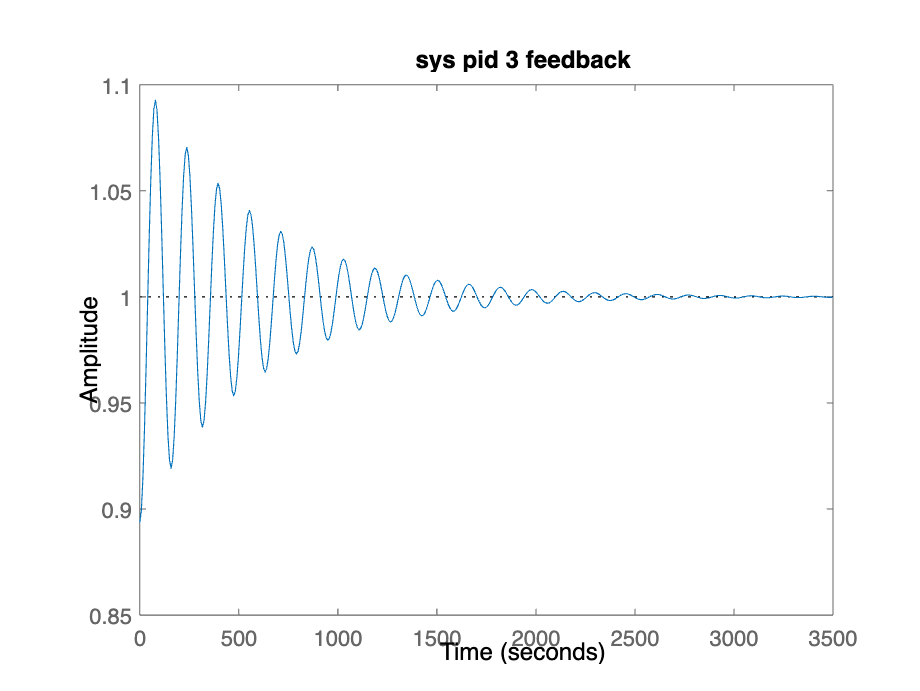

figure();
step(sys_pid_feedback);
title("sys pid 3 feedback");

%%lead changes
beta = acos(zeta);
beta = rad2deg(beta);
xpoint = -zeta*wn

xpoint = -0.0222

tan_beta = tan((beta*pi)/180);
ypoint = tan_beta*zeta*wn

ypoint = 0.0329


num1 = 0.002965;
den1 = [1 0.002965];
g1 = tf (num1,den1);



teta_p = 30;
teta_z = 59.61;
x = ypoint/(tan((30*pi)/180));
p = x + 0.0222

p = 0.0792

y = ypoint/(tan((59.61*pi)/180));
z = 0.0222-y

z = 0.0029


q = -0.0222 + 0.0328j ;
num2 = 0.002965*(q+z);
den2 = (q+p)*(q+0.002965);
%k = abs(den2/num2)
k=50

k = 50

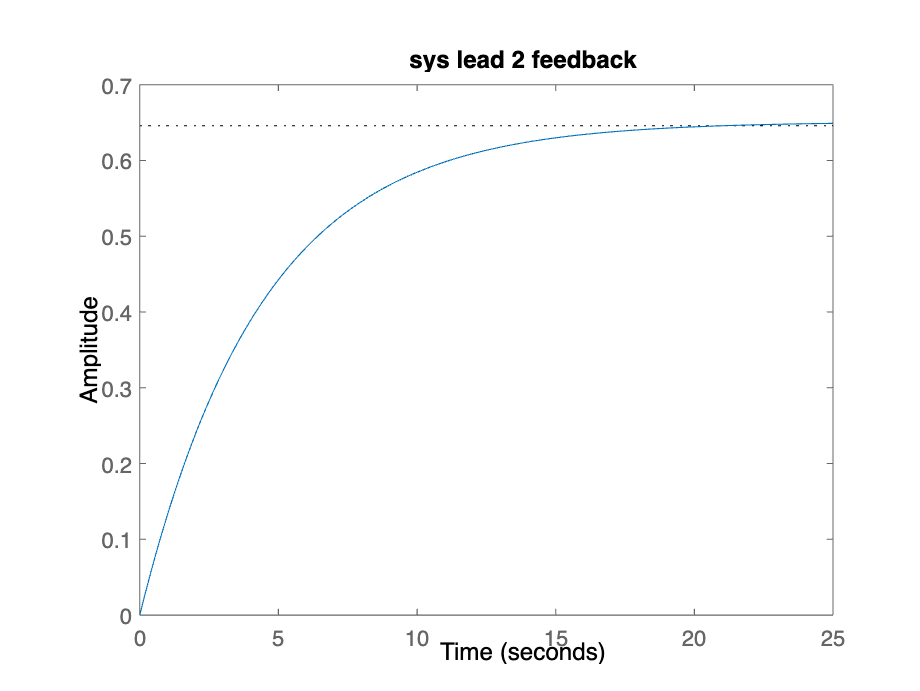



num3 = [k*0.002965 k*0.002965*z];
den3 = [1 0.002965+p 0.002965*p];
g2 = tf(num3,den3);
sys_lead_feedback=feedback(g2,1);
figure;
step(sys_lead_feedback);
title('sys lead 2 feedback')

stepinfo_lead=stepinfo(sys_lead_feedback)

stepinfo_lead = struct with fields:
         RiseTime: 9.3335
    TransientTime: 15.6677
     SettlingTime: 15.6677
      SettlingMin: 0.5832
      SettlingMax: 0.6505
        Overshoot: 0.7151
       Undershoot: 0
             Peak: 0.6505
         PeakTime: 30.1573


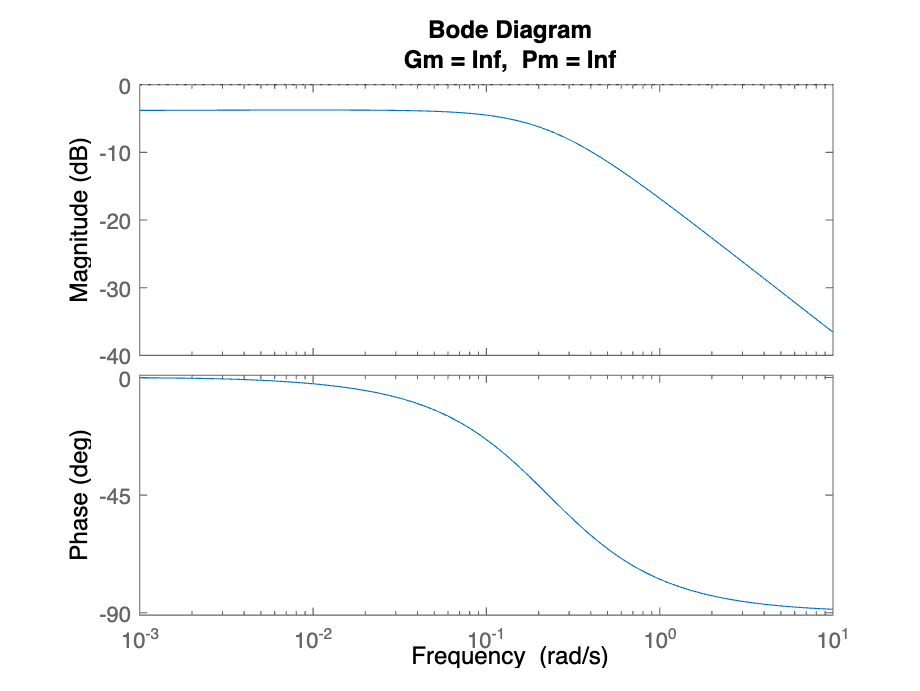

figure;
margin(sys_lead_feedback);


beta = acos(zeta);
beta = rad2deg(beta);
xpoint = -zeta*wn

xpoint = -0.0222

tan_beta = tan((beta*pi)/180);
ypoint = tan_beta*zeta*wn

ypoint = 0.0329


num1 = 0.002965;
den1 = [1 0.002965];
g1 = tf (num1,den1);



teta_p = 30;
teta_z = 75;
x = ypoint/(tan((30*pi)/180));
p = x + 0.0222

p = 0.0792

y = ypoint/(tan((75*pi)/180));
z = 0.0222-y

z = 0.0134


q = -0.0222 + 0.0328j ;
num2 = 0.002965*(q+z);
den2 = (q+p)*(q+0.002965);
%k = abs(den2/num2)
k=50

k = 50

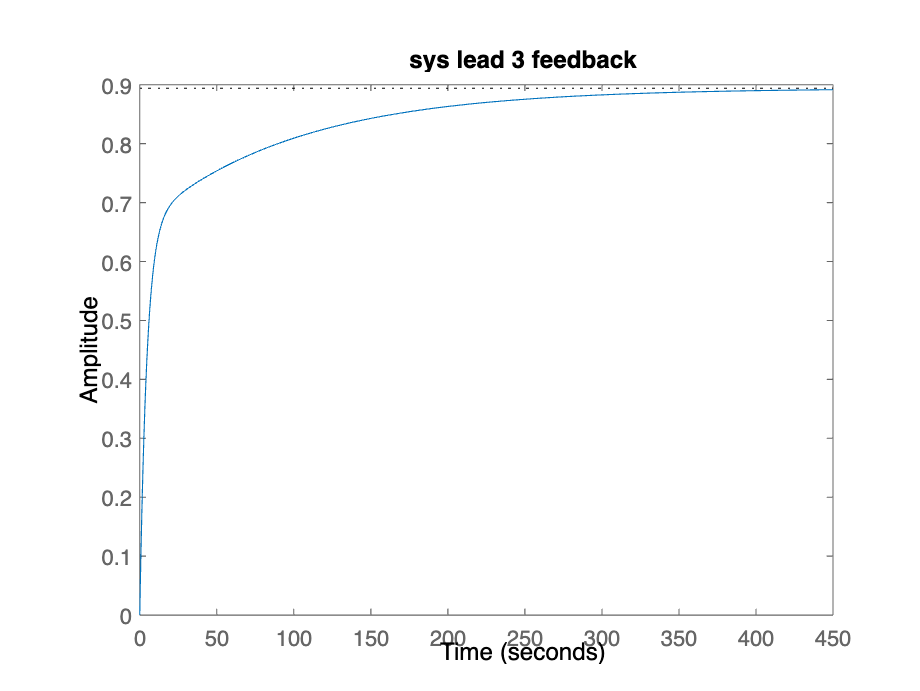



num3 = [k*0.002965 k*0.002965*z];
den3 = [1 0.002965+p 0.002965*p];
g2 = tf(num3,den3);
sys_lead_feedback=feedback(g2,1);
figure;
step(sys_lead_feedback);
title('sys lead 3 feedback')

stepinfo_lead=stepinfo(sys_lead_feedback)

stepinfo_lead = struct with fields:
         RiseTime: 94.0799
    TransientTime: 254.6371
     SettlingTime: 254.6371
      SettlingMin: 0.8048
      SettlingMax: 0.8923
        Overshoot: 0
       Undershoot: 0
             Peak: 0.8923
         PeakTime: 484.3792


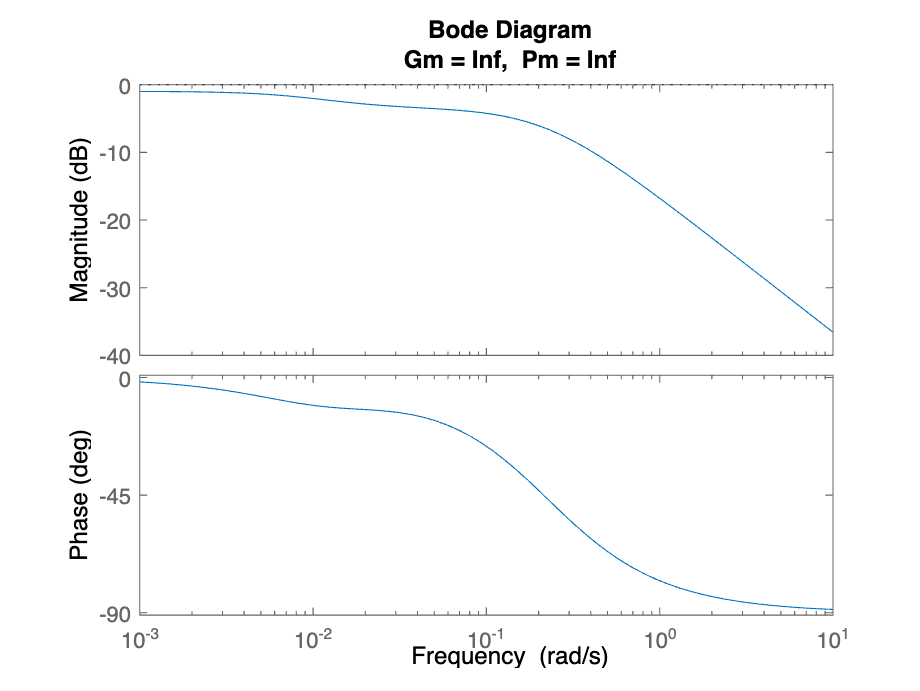

figure;
margin(sys_lead_feedback);

%%%lag changed
Gc_lag=10*(s+0.01)/(s+0.011785);
sys_lag=Gc_lag*sys;
sys_lag1_feedback=feedback(sys_lag,1);
stepinfo_lag1=stepinfo(sys_lag1_feedback)

stepinfo_lag1 = struct with fields:
         RiseTime: 72.5130
    TransientTime: 155.1783
     SettlingTime: 155.1783
      SettlingMin: 0.8070
      SettlingMax: 0.8934
        Overshoot: 0
       Undershoot: 0
             Peak: 0.8934
         PeakTime: 420.8311


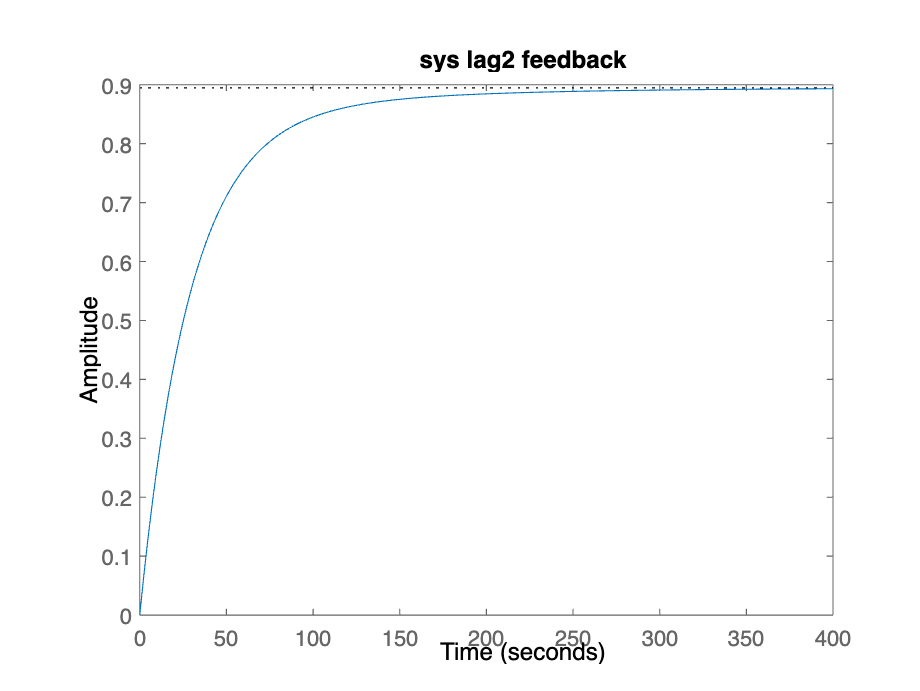

figure();
step(sys_lag1_feedback);
title("sys lag2 feedback");


Gc_lag=10*(s+1)/(s+0.011785);
sys_lag=Gc_lag*sys;
sys_lag1_feedback=feedback(sys_lag,1);
stepinfo_lag1=stepinfo(sys_lag1_feedback)

stepinfo_lag1 = struct with fields:
         RiseTime: 6.4070
    TransientTime: 168.4720
     SettlingTime: 168.4720
      SettlingMin: 0.5539
      SettlingMax: 1.6657
        Overshoot: 66.7642
       Undershoot: 0
             Peak: 1.6657
         PeakTime: 18.2328


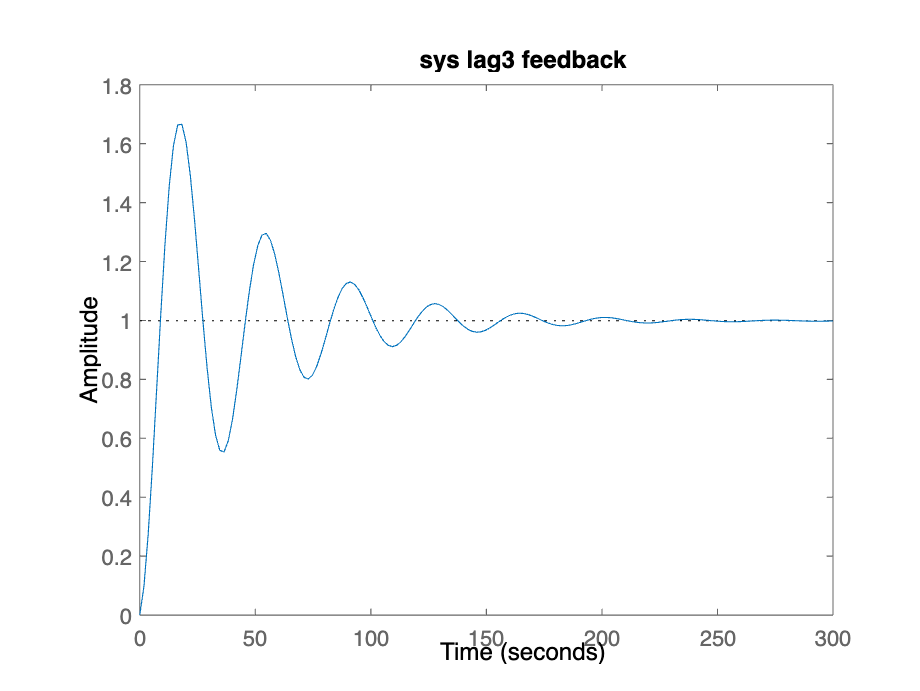

figure();
step(sys_lag1_feedback);
title("sys lag3 feedback");

%%% best controller
A=(-S1*sqrt(2*g))/(2*a);
B=1/a;
C=0.5*S1*sqrt(2*g);
D=0;
[num,den]=ss2tf(A,B,C,D);
sys_nonelinear=tf(num,den)

sys_nonelinear =
 
    0.007191
  ------------
  s + 0.007191
 
Continuous-time transfer function.



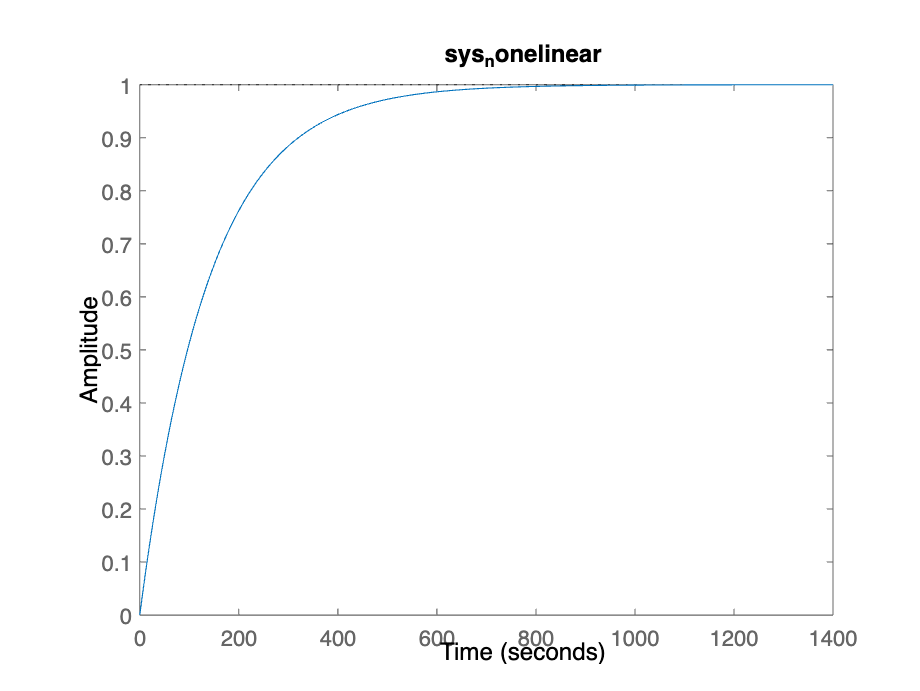

figure();
step(sys_nonelinear);
title("sys_nonelinear");

%% PI is the best (beacuse it has both overshoot and settling time goals
%%%PI
ki_2=(wn^2)/(0.002965);
Gc_pi=23+ki_2/s;

sys_pi=Gc_pi*sys;
sys_pi_feedback=feedback(sys_pi,1);
stepinfo_PI=stepinfo(sys_pi_feedback)

stepinfo_PI = struct with fields:
         RiseTime: 20.6354
    TransientTime: 130.0479
     SettlingTime: 130.0479
      SettlingMin: 0.9223
      SettlingMax: 1.1358
        Overshoot: 13.5786
       Undershoot: 0
             Peak: 1.1358
         PeakTime: 54.3543


figure;
step(sys_pi_feedback);
title("sys pi feedback");

sys_pi_nonelinear=Gc_pi*sys_nonelinear;
sys_pi_nonelinear_feedback=feedback(sys_pi_nonelinear,1);
stepinfo_PInonelinear=stepinfo(sys_pi_nonelinear_feedback)

stepinfo_PInonelinear = struct with fields:
         RiseTime: 10.8100
    TransientTime: 78.9362
     SettlingTime: 78.9362
      SettlingMin: 0.9141
      SettlingMax: 1.0577
        Overshoot: 5.7674
       Undershoot: 0
             Peak: 1.0577
         PeakTime: 30.8178


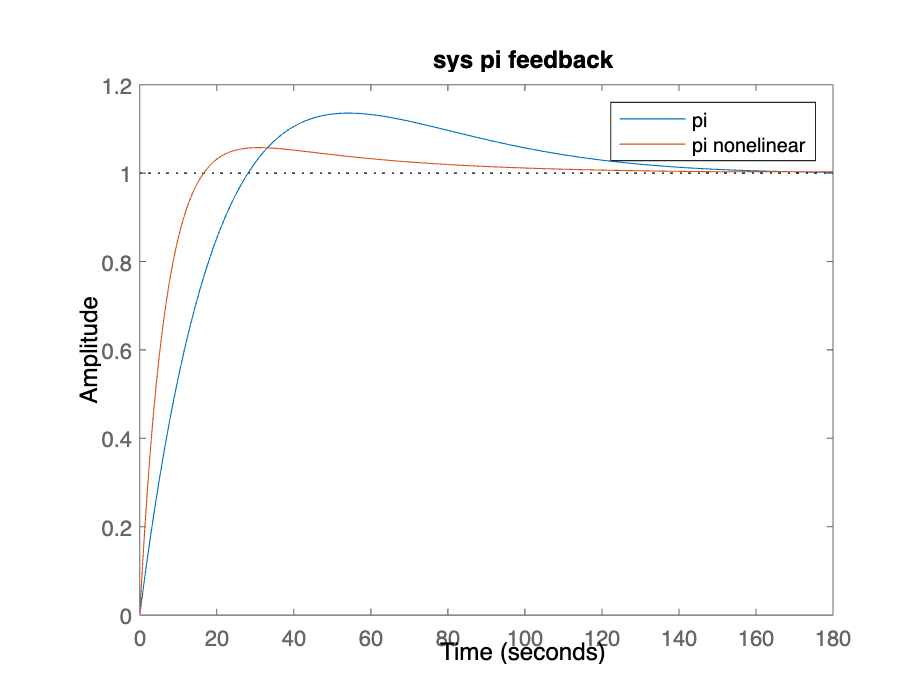

hold on
step(sys_pi_nonelinear_feedback);
% title("sys pi nonelinear feedback");
legend('pi','pi nonelinear')